## **Pk-Trailblazer Mission Model**

**Objective of the Simulation**

The primary objective of this simulation is to:

- Model the CubeSat's orbit dynamics and determine key orbital parameters.

- Simulate the power generation and consumption cycle of the Electrical Power System (EPS).

- Evaluate subsystem performance during different mission modes:

- Detumbling phase after deployment.

- Imaging operations over glacier regions.

- Data transmission during ground station passes.

- Safe mode activation under low-power conditions.

- Ensure that onboard systems maintain functionality throughout the mission.

**Key Subsystems Simulated**

Attitude Determination and Control System (ADCS):

- Stabilizes the CubeSat after deployment.

- Ensures precise pointing of the multispectral camera.

Electrical Power System (EPS):

- Models solar power generation and battery charge-discharge cycles.

- Simulates safe mode management during low-power scenarios.

Communication System (COM):

- Transmits payload data to the ground station.

- Ensures reliable telemetry and command uplink/downlink.

Payload (Multispectral Camera):

- Captures high-resolution images during nadir-pointing operations.

- Processes and compresses data onboard for efficient transmission

%%Initialize
clear
clc
close all

tic

**Define Key Locations**

This section defines the key geographic locations relevant to the CubeSat mission, including the Areas of Interest (AOIs) and the Ground Station (GS). These locations play a crucial role in planning the CubeSat's orbital path, imaging operations, and data transmission.

%%Define Key Locations
% Area of Interest (AOI)
AOIs.center_lat = 35.4212; % Siachen Glacier latitude
AOIs.center_long = 77.1090; % Siachen Glacier longitude
AOIs.radius_km = 200; % Radius of AOI in km

% Area of Interest (AOI)
AOIb.center_lat = 35.7128; % Blator Glacier latitude
AOIb.center_long = 76.5133; % Blatori Glacier longitude
AOIb.radius_km = 200; % Radius of AOI in km


% Ground Station (GS)
GS.lat = 33.6844; % Islamabad latitude
GS.long = 73.0479; % Islamabad longitude


%Mission Moded
% Mainttain mission modes 
% 0---- Detumble
% 1---- Active
% 2-----SafeMode

Mission_mode= 0; % 



**Electrical Power System (EPS) Parameters**

The following parameters define the CubeSat's Electrical Power System (EPS), which manages power generation, storage, and consumption to ensure all subsystems operate effectively throughout the mission.

**1. Solar Power Generation**

- **Solar Panel Area**: 0.1 m20.1 \, m^2

- Represents the total area of the deployed solar panels.

- **Panel Efficiency**: 28%28\%

- Indicates the efficiency of the solar panels in converting solar energy into electrical power.

- **Solar Constant**: 1361 W/m21361 \, W/m^2

- Represents the power per unit area received from the Sun at the CubeSat's orbital altitude.

**2. Battery Storage**

- **Battery Capacity**: 50 Watt-hours50 \, \text{Watt-hours}

- Total energy storage capacity of the onboard battery.

- **Battery Storage (Joules)**: 180,000 J180,000 \, J

- Converted to Joules for use in the simulation.

- **Initial Battery Level**: 180,000 J180,000 \, J

- Assumes a fully charged battery at the start of the mission.

- **Safe Mode Threshold**: 10%10\%

- If the battery level drops below 10% of its capacity, the satellite enters safe mode to conserve energy.

**3. Subsystem Power Consumption**

- **Power Baseline**: 5 W5 \, W

- Power required for the satellite bus, including the Onboard Computer (OBC) and sensors.

- **Power for Communication (Comm)**: 2 W2 \, W

- Power used during uplink/downlink operations with the ground station.

- **Power for Payload**: 6 W6 \, W

- Power required for operating the multispectral camera.

- **Power for ADCS**: 4 W4 \, W

- Power consumed during attitude stabilization and detumbling.

- **Power in Safe Mode**: 3 W3 \, W

- Reduced power consumption when the satellite operates with minimal functionality.

**4. Total Power Consumption**

- **Total Power**: power_total=power_baseline+(Additional Subsystem Power as Required)\text{power\_total} = \text{power\_baseline} + \text{(Additional Subsystem Power as Required)}

- For normal operation, this can include power for communication, payload, or ADCS depending on the active mode.

- During **Safe Mode**, only baseline and essential systems are powered.

**EPS Simulation Highlights**

- **Power Generation**: 

- Simulates solar power output based on the solar constant, panel area, and efficiency.

- **Power Usage**: 

- Tracks subsystem-specific consumption dynamically across different operational modes.

- **Battery Management**: 

- Monitors charge and discharge cycles, ensuring safe mode is triggered at critical battery levels.

This setup ensures reliable energy management to support mission objectives, such as data capture, processing, and communication, while maintaining satellite health.

% EPS Parameters
% EPS Parameters
solar_panel_area = 0.1; % Solar panel area (m^2)
panel_efficiency = 0.28; % Solar panel efficiency
solar_constant = 1361; % Solar constant (W/m^2)
battery_capacity = 50; % Battery capacity (Watt-hours)
battery_storage = battery_capacity * 3600; % Convert to Joules
initial_battery_level = battery_storage; % Initial battery charge (Joules)
safe_mode_threshold = 0.5 * battery_storage; % 10% battery level threshold for safe mode
% Subsystem Power Consumption (W)
power_baseline = 3; % Satellite bus (OBC, sensors)
power_comm = 2; % Communication system
power_payload = 4; % Payload
power_adcs = 4; % ADCS during detumbling
power_safe_mode = 3; % Safe mode power consumption

power_total=power_baseline ;


**Communication Parameters**

This section defines the key parameters and variables required for simulating the communication system of the CubeSat. The focus is on modeling data transmission from the satellite to the ground station using the AX.25 protocol.

**1. Data Variables**

- `data_to_transmit`: Payload data (in bytes) to be transmitted during a ground station pass. 

- Initialized to `0` and updated after each image capture.

- `data_remaining`: Tracks the remaining payload data (in bytes) that still needs to be transmitted. 

- Initialized to `0` and dynamically updated during transmission.

- `packet_idx`: Packet index to track the sequence of transmitted packets.

- `data_transmitted`: Cumulative amount of data (in bytes) successfully transmitted to the ground station.

**2. Communication System Parameters**

- **Data Rate (**`data_rate`**)**: 9600 bps9600 \, \text{bps}

- The transmission rate for data (bits per second).

- **Packet Size (**`packet_size`**)**: 256 bytes256 \, \text{bytes}

- Size of each data packet sent during a communication session.

- **Communication Time Step (**`comm_time_step`**)**: 10 s10 \, \text{s}

- Time step for updating transmission calculations.

**3. AX.25 Protocol Configuration**

The AX.25 protocol is used for reliable communication between the satellite and the ground station.

- **Preamble**: 

- `uint8([126, 126])` (or `0x7E, 0x7E`)

- Marks the start of a frame for proper synchronization.

- **Header Fields**: 

- **Source Address**: `'SAT001'`

- Identifies the satellite as the source of the transmission.

- **Destination Address**: `'GND001'`

- Identifies the ground station as the intended recipient.

- **Control Field**: `uint8(0x03)`

- Default AX.25 value for unnumbered information frames.

- **Protocol ID**: `uint8(0xF0)`

- Indicates an unconnected data transfer.

**4. Downlink Bandwidth**

- **Bandwidth (**`downlink_bandwidth`**)**: 2 MHz2 \, \text{MHz}

- Optional parameter for higher transmission rates. Adjust as needed for mission-specific constraints.

**Key Functionalities**

- **Image Transmission**: 

- After capturing an image, the payload data is queued for transmission.

- Data packets are transmitted sequentially until `data_remaining = 0`.

- **AX.25 Frame Structure**: 

- Each frame includes: 

- **Preamble**: Synchronization flag.

- **Header Fields**: Source/destination address, control field, and protocol ID.

- **Payload Data**: A chunk of the image or telemetry data.

- **Transmission Updates**: 

- Data is transmitted in packets of size `packet_size`.

- `data_remaining` is decremented by `packet_size` after each transmission step.

**Use in Simulation**

- **During Ground Station Pass**: 

- Simulate data transmission at the defined `data_rate`.

- Track the progress of `data_to_transmit`, `data_remaining`, and `data_transmitted`.

- **Data Preparation**: 

- Simulate data preparation with headers and metadata before transmission.

%Communication  Parameters
data_to_transmit= 0; % payload data
data_remaining = 0;  % Remaining data to transmit initalise after image capture
packet_idx=0;
data_transmitted=0;
%downlink_bandwidth=2*1e6; % Bandwidth 
comm_time_step = 10;
data_rate = 30 % Data rate (bits per second)

data_rate = 30

packet_size = 256; % Packet size (bytes)
preamble = uint8([126, 126]); % AX.25 preamble flag (0x7E)
% AX.25 Header Fields
source_address = 'SAT001'; % 6-character satellite ID
destination_address = 'GND001'; % 6-character ground station ID
control_field = uint8(0x03); % Control field (default AX.25 value)
protocol_id = uint8(0xF0); % Protocol ID for unconnected data transfer




%Payload
Payload.imageData = {}; % Stores images
Payload.Sent = {}; % Status of whether the image has been sent
 % 


## Initialize Log

comm_status = struct('time', [], 'data_transmitted', [], 'data_remaining', [], 'downlink_times', []);
downlink_start = NaN; % To track start of downlink



**Global Variables for ADCS Simulation**

The following global variables are defined for the Attitude Determination and Control System (ADCS) simulation, focusing on **magnetometers** and **magnetorquers**. These variables are used throughout the simulation to model sensor measurements, actuator responses, and satellite dynamics.

**1. Satellite Dynamics**

- `BI`: Satellite's body inertia matrix.

- `BB`: Satellite's body magnetic field vector.

- `m`: Satellite's mass (kg).

- `I`: Inertia tensor of the satellite in body frame.

- `Is`: Rotational inertia of reaction wheels or other actuators.

- `invI`: Inverse of the inertia tensor for faster computations.

- `mu`: Gravitational parameter of Earth (μ=398600 km3/s2\mu = 398600 \, \text{km}^3/\text{s}^2).

**2. Sensor and Navigation Variables**

- `lastMagUpdate`: Time of the last magnetic field measurement update.

- `nextMagUpdate`: Time of the next scheduled magnetic field measurement.

- `lastSensorUpdate`: Time of the last general sensor update.

- `nextSensorUpdate`: Time of the next scheduled sensor update.

- **Magnetometer Measurements**:

- `BfieldMeasured`: Magnetic field measured by the onboard magnetometers.

- `BfieldNav`: Navigation estimate of the magnetic field.

- `BfieldNavPrev`: Previous navigation estimate of the magnetic field.

- **Gyroscope and Angular Velocity Measurements**:

- `pqrMeasured`: Measured angular velocities in body frame.

- `pqrNav`: Navigation estimate of angular velocity.

- `pqrNavPrev`: Previous angular velocity navigation estimate.

- **Euler Angles**:

- `ptpMeasured`: Measured Euler angles (pitch, yaw, roll).

- `ptpNav`: Navigation estimate of Euler angles.

- `ptpNavPrev`: Previous Euler angles navigation estimate.

**3. Magnetorquer and Satellite Control**

- `current`: Current applied to the magnetorquers.

- `Ir1Bcg, Ir2Bcg, Ir3Bcg`: Current values for each magnetorquer relative to the satellite's center of gravity.

- `Ir1B, Ir2B, Ir3B`: Current values for magnetorquers in body-fixed frame.

- `maxSpeed`: Maximum angular speed of the satellite.

- `maxAlpha`: Maximum angular acceleration of the satellite.

**5. Sensor and Actuator Models**

- `fsensor`: Sensor sampling frequency.

- **Sensor Bias**: 

- `MagFieldBias`: Bias in magnetometer measurements.

- `AngFieldBias`: Bias in angular velocity measurements.

- `EulerBias`: Bias in Euler angle measurements.

- **Sensor Noise**: 

- `MagFieldNoise`: Magnetometer noise.

- `AngFieldNoise`: Angular velocity noise.

- `EulerNoise`: Euler angle noise.

**6. Aerodynamics and Drag**

- `R`: Position vector of the satellite in orbit.

- `Amax`: Maximum projected surface area of the satellite for drag calculations.

- `lmax`: Maximum satellite length (for torque calculations).

- `CD`: Drag coefficient of the satellite.

**Usage**

These global variables allow for seamless sharing of key parameters across simulation functions, ensuring consistent modeling of the following:

- **Magnetometer Measurements**: 

- Real-time magnetic field data for attitude determination.

- **Magnetorquer Control**: 

- Actuator responses to reduce angular velocities or stabilize orientation.

- **Sensor Fusion**: 

- Integration of noisy, biased measurements into accurate state estimates.


%%%Globals
global BI BB m I Is invI mu lastMagUpdate nextMagUpdate lastSensorUpdate 
global nextSensorUpdate BfieldMeasured pqrMeasured ptpMeasured BfieldNav pqrNav ptpNav
global BfieldNavPrev pqrNavPrev ptpNavPrev current Ir1Bcg Ir2Bcg Ir3Bcg n1 n2 n3
global maxSpeed maxAlpha Ir1B Ir2B Ir3B rwalphas
global fsensor MagFieldBias AngFieldBias EulerBias R Amax lmax CD
global MagFieldNoise AngFieldNoise EulerNoise IrR Jinv
 
%%%%Initialize Nav Filter
BfieldNavPrev = [-99;0;0];
pqrNavPrev = [0;0;0];
ptpNavPrev = [0;0;0];




nextMagUpdate = 1;
lastMagUpdate = 0;

%%%Get Planet Parameters
planet

%%%Get mass and inertia properties
inertia

**Description of Initial Conditions for CubeSat Simulation**

This section sets up the initial conditions for the CubeSat's orbital and attitude simulation. These values define the starting position, velocity, attitude, angular velocity, and reaction wheel states, which are critical for modeling the satellite's dynamics.

**1. Orbital Position and Velocity**

- **Altitude**: 600,000 m(600 km)600,000 \, \`text{m} (600 \, \text{km})`

- The satellite’s altitude above Earth's surface.

- **Initial Position (**`x0`**, **`y0`**, **`z0`**)**:

- `x0`: The satellite is initialized at R+altitudeR +` \text{altitude}` (Earth's radius + altitude).

- `y0` and `z0`: Set to 00, placing the satellite on the equatorial plane at the start.

- **Circular Velocity (**`vcircular`**)**:

- Computed using the formula: `vcircular=μav_\text{circular} = \sqrt{\frac{\mu}{a}}`Where: 

- μ\mu: Earth's gravitational constant (398,600 km3/s2398,600 \, \`text{km}^3/\text{s}^2).`

- aa: Semi-major axis (R+altitudeR + \text{altitude}).

- **Initial Velocities (**`xdot0`**, **`ydot0`**, **`zdot0`**)**:

- `xdot0`: Set to 00, as the initial velocity is purely tangential.

- `ydot0`: Computed as vcircular⋅cos (inclination)v_\text{circular} \cdot \cos(\text{inclination}).

- `zdot0`: Computed as vcircular⋅sin (inclination)v_\text{circular} \cdot \sin(\text{inclination}).

- **Inclination**: 35∘35^\circ (converted to radians).

**2. Attitude and Angular Velocity**

- **Initial Euler Angles (**`phi0`**, **`theta0`**, **`psi0`**)**:

- Set to 0∘0^\circ (no initial rotation).

- Represents roll, pitch, and yaw in radians.

This ensures compatibility with attitude propagation in 3D space.

- **Initial Angular Velocities (**`p0`**, **`q0`**, **`r0`**)**:

- `p0`: 1.8 rad/s1.8 \,` \text{rad/s}` (initial roll rate).

- `q0`: −0.5 rad/s-0.5 \,` \text{rad/s}` (initial pitch rate).

- `r0`: 0.3 rad/s0.3 \, `\text{rad/s} `(initial yaw rate).

- These values simulate the satellite’s initial tumbling after deployment.

**4. Simulation Time Window**

- **Orbital Period (**`period`**)**:

- Calculated using Kepler’s Third Law:` T=3πa3μT = 3\pi \sqrt{\frac{a^{3}}{\mu}}`Where: 

- aa: Semi-major axis.

- μ\mu: Earth’s gravitational constant.

- **Number of Orbits**:

- The simulation runs for one orbit `(Tfinal=periodT_{\text{final}} = \text{period}).`

- **Time Step (**`timestep`**)**:

- Set to 1.0 s1.0 \, \text{s} for high temporal resolution.

- **Time Vector (**`tout`**)**:

- Discretized time steps from 00 to `TfinalT_{\text{final}} `for numerical integration.

**5. State Initialization**

- **State Vector (**`state`**)**:

- Combines all initial conditions: state=[x0,y0,z0,x˙0,y˙0,z˙0,q01230,p0,q0,r0]\text{state} = [x_0, y_0, z_0, \dot{x}_0, \dot{y}_0, \dot{z}_0, q_{0123_0}, p_0, q_0, r_0]

- Represents the satellite’s position, velocity, orientation (quaternions), and angular velocities.

- **State Output (**`stateout`**)**:

- Pre-allocated matrix to store the state at each time step for post-simulation analysis.

**Simulation Purpose**

These initial conditions serve as the starting point for:

- **Orbital Dynamics Simulation**: 

- Propagation of position and velocity to model the CubeSat’s trajectory.

- **Attitude Dynamics Simulation**: 

- Stabilizing the CubeSat using ADCS (magnetorquers and reaction wheels).

- **Subsystem Interactions**: 

- Integration of orbital and attitude states with payload and communication models.

Would you like further help in adding visualization or diagnostics for these conditions?

%%%Initial Conditions Position and Velocity
altitude = 600*1000; %%meters
x0 = R + altitude;
y0 = 0;
z0 = 0; 
xdot0 = 0;
inclination =35*pi/180;

semi_major = norm([x0;y0;z0]);
vcircular = sqrt(mu/semi_major);
ydot0 = vcircular*cos(inclination);
zdot0 = vcircular*sin(inclination);

%%%Intitial Conditions for Attitude and Angular Velocity
phi0 = 0;
theta0 = 0;
psi0 = 0;
ptp0 = [phi0;theta0;psi0];
q0123_0 = EulerAngles2Quaternions(ptp0);


p0 = 1.8;
q0 = -0.5;
r0 = 0.3;
%%%Initial conditions of my reaction wheels
% w10 = 0;
% w20 = 0;
% w30 = 0;



state = [x0;y0;z0;xdot0;ydot0;zdot0;q0123_0;p0;q0;r0];

%%%Need time window
period = 3*pi/sqrt(mu)*semi_major^(3/2);
number_of_orbits = 1;
tfinal = period*number_of_orbits;
%tfinal = 100;
next = 10;
timestep = 1.0;
tout = 0:timestep:tfinal;
stateout = zeros(length(tout),length(state));


%%%%%%%%

**Description of Code for EPS Initialization**

This section initializes the variables required for simulating the **Electrical Power System (EPS)**, which manages energy generation, storage, and consumption throughout the mission. The EPS interacts dynamically with the CubeSat's state (position, orientation, and subsystems) to ensure uninterrupted operation.

**1. EPS State Variables**

- `battery_level`:

- Stores the battery level at each time step (in Joules).

- Initialized with the `initial_battery_level`, representing a fully charged state.

- `solar_power`:

- Tracks the solar power generated at each time step (in Watts).

- Depends on the satellite's exposure to sunlight.

- `energy_consumed`:

- Tracks the total energy consumed by all subsystems during the mission (in Joules).

- Updated dynamically based on the active mode of the satellite.

**2. Subsystem Mode Tracking**

- `subsystem_mode`:

- Tracks the current operational mode of the satellite at each time step.

- Possible modes include: 

- **Detumbling**: Active immediately after deployment.

- **Payload Operation**: Imaging and scientific data collection.

- **Communication**: Downlink to the ground station.

- **Safe Mode**: Activated when battery levels fall below a critical threshold.

- `in_sunlight`:

- Boolean flag indicating whether the satellite is in sunlight or eclipse at each time step.

- Determines whether the solar panels are generating power.

- `is_safe_mode`:

- Global flag for safe mode activation.

- Ensures minimal power consumption to protect critical systems during low-energy conditions.

% Initialize variables EPS
battery_level = zeros(length(tout), 1); % Battery level (Joules)
solar_power = zeros(length(tout), 1); % Solar power output (W)
energy_consumed = zeros(length(tout), 1); % Energy consumed (Joules)
subsystem_mode = cell(length(tout), 1); % Subsystem operation mode
in_sunlight = true(length(tout), 1); % Sunlight or eclipse state
battery_level(1) = initial_battery_level; % Initial battery level
is_safe_mode = false; % Safe mode flag





%%%This is where we integrate the equations of motion

%%%Loop through time to integrate
BxBout = 0*stateout(:,1);
ByBout = BxBout;
BzBout = BxBout;
BxBm = 0*stateout(:,1);
ByBm = BxBout;
BzBm = BxBout;
pqrm = zeros(length(tout),3);

ptpm = zeros(length(tout),3);
ptpN = 0*ptpm;

BxBN = 0*stateout(:,1);
ByBN = BxBout;
BzBN = BxBout;
pqrN = zeros(length(tout),3);

ix = 0*stateout(:,1);
iy = ix;
iz = ix;

%rwa = 0*ptpm;

**Description of Sensor Parameters and Derivatives Initialization**

This section initializes the sensor parameters and calls the derivatives routine to set up the necessary variables for simulating the CubeSat's dynamics. It also prepares the simulation loop to compute the satellite's behavior over the specified time steps.

%%%Sensor Parameters
lastSensorUpdate = 0;
sensor_params

%%%%Call the Derivatives Routine to initialize vars
k1 = Satellite(tout(1),state);

%%%Print Next
lastPrint = 0;
for idx = 1:length(tout)
    %%%Save the current state
    stateout(idx,:) = state';
    
    %%%Save the Current
    ix(idx) = current(1);
    iy(idx) = current(2);
    iz(idx) = current(3);
    
    % %%%%Save reaction wheel acceleration
    % rwa(idx,:) = rwalphas';
    
    %%%Save the magnetic field
    BxBout(idx) = BB(1);
    ByBout(idx) = BB(2);
    BzBout(idx) = BB(3);


%%%% tracing of intermediat results

 Btemp(idx,1) = BI(1);
    Btemp(idx,2) = BI(2);
    Btemp(idx,3) = BI(3);



    %%%Save the Measured Magnetic field
    BxBm(idx) = BfieldMeasured(1);
    ByBm(idx) = BfieldMeasured(2);
    BzBm(idx) = BfieldMeasured(3);
    %%%Save the Nav magnetic field
    BxBN(idx) = BfieldNav(1);
    ByBN(idx) = BfieldNav(2);
    BzBN(idx) = BfieldNav(3);
    %%%THe actual pqr truth signal is embedded in
    %%%The state vector.
    %%%Save the measured pqr signal
    pqrm(idx,:) = pqrMeasured';
    %%%Save the Nav pqr signal
    pqrN(idx,:) = pqrNav';
    %%%Save ptp
    ptpm(idx,:) = ptpMeasured';
    ptpN(idx,:) = ptpNav';

Detumbling 
Detumbling 
Detumbling 
Detumbling 
Detumbling 
Detumbling 
Detumbling 
Detumbling 
Detumbling 
Detumbling 
Detumbling 
Detumbling 
Detumbling 
Detumbling 
Detumbling 
Detumbling 
Detumbling 
Detumbling 
Detumbling 
Detumbling 
Detumbling 
Detumbling 
Detumbling 
Detumbling 
Detumbling 
Detumbling 
Detumbling 
Detumbling 
Detumbling 
Detumbling 
Detumbling 
Detumbling 
Detumbling 
Detumbling 
Detumbling 
Detumbling 
Detumbling 
Detumbling 
Detumbling 
Detumbling 
Detumbling 
Detumbling 
Detumbling 
Detumbling 
Detumbling 
Detumbling 
Detumbling 
Detumbling 
Detumbling 
Detumbling 
Detumbling 
Detumbling 
Detumbling 
Detumbling 
Detumbling 
Detumbling 
Detumbling 
Detumbling 
Detumbling 
Detumbling 
Detumbling 
Detumbling 
Detumbling 
Detumbling 
Detumbling 
Detumbling 
Detumbling 
Detumbling 
Detumbling 
Detumbling 
Detumbling 
Detumbling 
Detumbling 
Detumbling 
Detumbling 
Detumbling 
Detumbling 
Detumbling 
Detumbling 
Detumbling 
Detumbling 
Detumbling 
Detumbling 
Detu

Time: 1188.0 s - CubeSat is over the Ground Station.
Time: 1189.0 s - CubeSat is over the Ground Station.
Time: 1190.0 s - CubeSat is over the Ground Station.
Time: 1191.0 s - CubeSat is over the Ground Station.
Time: 1192.0 s - CubeSat is over the Ground Station.
Time: 1193.0 s - CubeSat is over the Ground Station.
Time: 1194.0 s - CubeSat is over the Ground Station.
Time: 1195.0 s - CubeSat is over the Ground Station.
Time: 1196.0 s - CubeSat is over the Ground Station.
Time: 1197.0 s - CubeSat is over the Ground Station.
Time: 1198.0 s - CubeSat is over the Ground Station.
Time: 1199.0 s - CubeSat is over the Ground Station.
Time: 1200.0 s - CubeSat is over the Ground Station.
Time: 1201.0 s - CubeSat is over the Ground Station.
Time: 1202.0 s - CubeSat is over the Ground Station.
Time: 1203.0 s - CubeSat is over the Ground Station.
Time: 1204.0 s - CubeSat is over the Ground Station.
Time: 1205.0 s - CubeSat is over the Ground Station.
Time: 1206.0 s - CubeSat is over the Ground St

Time: 1257.0 s - CubeSat is over Baltoro.


Imaging Mode: Capturing image...


Time: 1258.0 s - CubeSat is over the Ground Station.


Time: 1258.0 s - Data Pakect Transmitted: 1.00 MB, Data Remaining: 255.00 MB
Time: 1258.0 s - Data Pakect Transmitted: 2.00 MB, Data Remaining: 254.00 MB
Time: 1258.0 s - Data Pakect Transmitted: 3.00 MB, Data Remaining: 253.00 MB
Time: 1258.0 s - Data Pakect Transmitted: 4.00 MB, Data Remaining: 252.00 MB
Time: 1258.0 s - Data Pakect Transmitted: 5.00 MB, Data Remaining: 251.00 MB
Time: 1258.0 s - Data Pakect Transmitted: 6.00 MB, Data Remaining: 250.00 MB
Time: 1258.0 s - Data Pakect Transmitted: 7.00 MB, Data Remaining: 249.00 MB
Time: 1258.0 s - Data Pakect Transmitted: 8.00 MB, Data Remaining: 248.00 MB
Time: 1258.0 s - Data Pakect Transmitted: 9.00 MB, Data Remaining: 247.00 MB
Time: 1258.0 s - Data Pakect Transmitted: 10.00 MB, Data Remaining: 246.00 MB
Time: 1258.0 s - Data Pakect Transmitted: 11.00 MB, Data Remaining: 245.00 MB
Time: 1258.0 s - Data Pakect Transmitted: 12.00 MB, Data Remaining: 244.00 MB
Time: 1258.0

Time: 1258.0 s - CubeSat is over Baltoro.


Imaging Mode: Capturing image...


Time: 1258.0 s - CubeSat is over Siachen.


Imaging Mode: Capturing image...


Time: 1259.0 s - CubeSat is over the Ground Station.


Time: 1259.0 s - Data Pakect Transmitted: 51.00 MB, Data Remaining: 205.00 MB
Time: 1259.0 s - Data Pakect Transmitted: 52.00 MB, Data Remaining: 204.00 MB
Time: 1259.0 s - Data Pakect Transmitted: 53.00 MB, Data Remaining: 203.00 MB
Time: 1259.0 s - Data Pakect Transmitted: 54.00 MB, Data Remaining: 202.00 MB
Time: 1259.0 s - Data Pakect Transmitted: 55.00 MB, Data Remaining: 201.00 MB
Time: 1259.0 s - Data Pakect Transmitted: 56.00 MB, Data Remaining: 200.00 MB
Time: 1259.0 s - Data Pakect Transmitted: 57.00 MB, Data Remaining: 199.00 MB
Time: 1259.0 s - Data Pakect Transmitted: 58.00 MB, Data Remaining: 198.00 MB
Time: 1259.0 s - Data Pakect Transmitted: 59.00 MB, Data Remaining: 197.00 MB
Time: 1259.0 s - Data Pakect Transmitted: 60.00 MB, Data Remaining: 196.00 MB
Time: 1259.0 s - Data Pakect Transmitted: 61.00 MB, Data Remaining: 195.00 MB
Time: 1259.0 s - Data Pakect Transmitted: 62.00 MB, Data Remaining: 194.00 MB
Time: 1259.0 s - Data Pakect Transmitted: 63.00 MB, Data Remaini

Time: 1259.0 s - CubeSat is over Baltoro.


Imaging Mode: Capturing image...


Time: 1259.0 s - CubeSat is over Siachen.


Imaging Mode: Capturing image...


Time: 1260.0 s - CubeSat is over Baltoro.


Imaging Mode: Capturing image...


Time: 1260.0 s - CubeSat is over Siachen.


Imaging Mode: Capturing image...


Time: 1261.0 s - CubeSat is over Baltoro.


Imaging Mode: Capturing image...


Time: 1261.0 s - CubeSat is over Siachen.


Imaging Mode: Capturing image...


Time: 1262.0 s - CubeSat is over Baltoro.


Imaging Mode: Capturing image...


Time: 1262.0 s - CubeSat is over Siachen.


Imaging Mode: Capturing image...


Time: 1263.0 s - CubeSat is over Baltoro.


Imaging Mode: Capturing image...


Time: 1263.0 s - CubeSat is over Siachen.


Imaging Mode: Capturing image...


Time: 1264.0 s - CubeSat is over Baltoro.


Imaging Mode: Capturing image...


Time: 1264.0 s - CubeSat is over Siachen.


Imaging Mode: Capturing image...


Time: 1265.0 s - CubeSat is over Baltoro.


Imaging Mode: Capturing image...


Time: 1265.0 s - CubeSat is over Siachen.


Imaging Mode: Capturing image...


Time: 1266.0 s - CubeSat is over Baltoro.


Imaging Mode: Capturing image...


Time: 1266.0 s - CubeSat is over Siachen.


Imaging Mode: Capturing image...


Time: 1267.0 s - CubeSat is over Baltoro.


Imaging Mode: Capturing image...


Time: 1267.0 s - CubeSat is over Siachen.


Imaging Mode: Capturing image...


Time: 1268.0 s - CubeSat is over Baltoro.


Imaging Mode: Capturing image...


Time: 1268.0 s - CubeSat is over Siachen.


Imaging Mode: Capturing image...


Time: 1269.0 s - CubeSat is over Baltoro.


Imaging Mode: Capturing image...


Time: 1269.0 s - CubeSat is over Siachen.


Imaging Mode: Capturing image...


Time: 1270.0 s - CubeSat is over Baltoro.


Imaging Mode: Capturing image...


Time: 1270.0 s - CubeSat is over Siachen.


Imaging Mode: Capturing image...


Time: 1271.0 s - CubeSat is over Baltoro.


Imaging Mode: Capturing image...


Time: 1271.0 s - CubeSat is over Siachen.


Imaging Mode: Capturing image...


Time: 1272.0 s - CubeSat is over Baltoro.


Imaging Mode: Capturing image...


Time: 1272.0 s - CubeSat is over Siachen.


Imaging Mode: Capturing image...


Time: 1273.0 s - CubeSat is over Baltoro.


Imaging Mode: Capturing image...


Time: 1273.0 s - CubeSat is over Siachen.


Imaging Mode: Capturing image...


Time: 1274.0 s - CubeSat is over Baltoro.


Imaging Mode: Capturing image...


Time: 1274.0 s - CubeSat is over Siachen.


Imaging Mode: Capturing image...


Time: 1275.0 s - CubeSat is over Baltoro.


Imaging Mode: Capturing image...


Time: 1275.0 s - CubeSat is over Siachen.


Imaging Mode: Capturing image...


Time: 1276.0 s - CubeSat is over Baltoro.


Imaging Mode: Capturing image...


Time: 1276.0 s - CubeSat is over Siachen.


Imaging Mode: Capturing image...


Time: 1277.0 s - CubeSat is over Baltoro.


Imaging Mode: Capturing image...


Time: 1277.0 s - CubeSat is over Siachen.


Imaging Mode: Capturing image...


Time: 1278.0 s - CubeSat is over Baltoro.


Imaging Mode: Capturing image...


Time: 1278.0 s - CubeSat is over Siachen.


Imaging Mode: Capturing image...


Time: 1279.0 s - CubeSat is over Baltoro.


Imaging Mode: Capturing image...


Time: 1279.0 s - CubeSat is over Siachen.


Imaging Mode: Capturing image...


Time: 1280.0 s - CubeSat is over Baltoro.


Imaging Mode: Capturing image...


Time: 1280.0 s - CubeSat is over Siachen.


Imaging Mode: Capturing image...


Time: 1281.0 s - CubeSat is over Baltoro.


Imaging Mode: Capturing image...


Time: 1281.0 s - CubeSat is over Siachen.


Imaging Mode: Capturing image...


Time: 1282.0 s - CubeSat is over Baltoro.


Imaging Mode: Capturing image...


Time: 1282.0 s - CubeSat is over Siachen.


Imaging Mode: Capturing image...


Time: 1283.0 s - CubeSat is over Baltoro.


Imaging Mode: Capturing image...


Time: 1283.0 s - CubeSat is over Siachen.


Imaging Mode: Capturing image...


Time: 1284.0 s - CubeSat is over Baltoro.


Imaging Mode: Capturing image...


Time: 1284.0 s - CubeSat is over Siachen.


Imaging Mode: Capturing image...


Time: 1285.0 s - CubeSat is over Baltoro.


Imaging Mode: Capturing image...


Time: 1285.0 s - CubeSat is over Siachen.


Imaging Mode: Capturing image...


Time: 1286.0 s - CubeSat is over Baltoro.


Imaging Mode: Capturing image...


Time: 1286.0 s - CubeSat is over Siachen.


Imaging Mode: Capturing image...


Time: 1287.0 s - CubeSat is over Baltoro.


Imaging Mode: Capturing image...


Time: 1287.0 s - CubeSat is over Siachen.


Imaging Mode: Capturing image...


Time: 1288.0 s - CubeSat is over Baltoro.


Imaging Mode: Capturing image...


Time: 1288.0 s - CubeSat is over Siachen.


Imaging Mode: Capturing image...


Time: 1289.0 s - CubeSat is over Baltoro.


Imaging Mode: Capturing image...


Time: 1289.0 s - CubeSat is over Siachen.


Imaging Mode: Capturing image...


Time: 1290.0 s - CubeSat is over Baltoro.


Imaging Mode: Capturing image...


Time: 1290.0 s - CubeSat is over Siachen.


Imaging Mode: Capturing image...


Time: 1291.0 s - CubeSat is over Siachen.


Imaging Mode: Capturing image...


Time: 1292.0 s - CubeSat is over Siachen.


Imaging Mode: Capturing image...


Time: 1293.0 s - CubeSat is over Siachen.


Imaging Mode: Capturing image...


Time: 1294.0 s - CubeSat is over Siachen.


Imaging Mode: Capturing image...


Time: 1295.0 s - CubeSat is over Siachen.


Imaging Mode: Capturing image...


Time: 1296.0 s - CubeSat is over Siachen.


Imaging Mode: Capturing image...


Time: 1297.0 s - CubeSat is over Siachen.


Imaging Mode: Capturing image...


Time: 1298.0 s - CubeSat is over Siachen.


Imaging Mode: Capturing image...


Time: 1299.0 s - CubeSat is over Siachen.


Imaging Mode: Capturing image...


Time: 1300.0 s - CubeSat is over Siachen.


Imaging Mode: Capturing image...


Time: 1301.0 s - CubeSat is over Siachen.


Imaging Mode: Capturing image...


Time: 1302.0 s - CubeSat is over Siachen.


Imaging Mode: Capturing image...


Time: 1303.0 s - CubeSat is over Siachen.


Imaging Mode: Capturing image...


Time: 6982.0 s - CubeSat is over the Ground Station.


Time: 6982.0 s - Data Pakect Transmitted: 101.00 MB, Data Remaining: 155.00 MB
Time: 6982.0 s - Data Pakect Transmitted: 102.00 MB, Data Remaining: 154.00 MB
Time: 6982.0 s - Data Pakect Transmitted: 103.00 MB, Data Remaining: 153.00 MB
Time: 6982.0 s - Data Pakect Transmitted: 104.00 MB, Data Remaining: 152.00 MB
Time: 6982.0 s - Data Pakect Transmitted: 105.00 MB, Data Remaining: 151.00 MB
Time: 6982.0 s - Data Pakect Transmitted: 106.00 MB, Data Remaining: 150.00 MB
Time: 6982.0 s - Data Pakect Transmitted: 107.00 MB, Data Remaining: 149.00 MB
Time: 6982.0 s - Data Pakect Transmitted: 108.00 MB, Data Remaining: 148.00 MB
Time: 6982.0 s - Data Pakect Transmitted: 109.00 MB, Data Remaining: 147.00 MB
Time: 6982.0 s - Data Pakect Transmitted: 110.00 MB, Data Remaining: 146.00 MB
Time: 6982.0 s - Data Pakect Transmitted: 111.00 MB, Data Remaining: 145.00 MB
Time: 6982.0 s - Data Pakect Transmitted: 112.00 MB, Data Remaining: 144.00 MB
Time: 6982.0 s - Data Pakect Transmitted: 113.00 MB,

Time: 6983.0 s - CubeSat is over the Ground Station.


Time: 6983.0 s - Data Pakect Transmitted: 151.00 MB, Data Remaining: 105.00 MB
Time: 6983.0 s - Data Pakect Transmitted: 152.00 MB, Data Remaining: 104.00 MB
Time: 6983.0 s - Data Pakect Transmitted: 153.00 MB, Data Remaining: 103.00 MB
Time: 6983.0 s - Data Pakect Transmitted: 154.00 MB, Data Remaining: 102.00 MB
Time: 6983.0 s - Data Pakect Transmitted: 155.00 MB, Data Remaining: 101.00 MB
Time: 6983.0 s - Data Pakect Transmitted: 156.00 MB, Data Remaining: 100.00 MB
Time: 6983.0 s - Data Pakect Transmitted: 157.00 MB, Data Remaining: 99.00 MB
Time: 6983.0 s - Data Pakect Transmitted: 158.00 MB, Data Remaining: 98.00 MB
Time: 6983.0 s - Data Pakect Transmitted: 159.00 MB, Data Remaining: 97.00 MB
Time: 6983.0 s - Data Pakect Transmitted: 160.00 MB, Data Remaining: 96.00 MB
Time: 6983.0 s - Data Pakect Transmitted: 161.00 MB, Data Remaining: 95.00 MB
Time: 6983.0 s - Data Pakect Transmitted: 162.00 MB, Data Remaining: 94.00 MB
Time: 6983.0 s - Data Pakect Transmitted: 163.00 MB, Data 

Time: 6984.0 s - CubeSat is over the Ground Station.


Time: 6984.0 s - Data Pakect Transmitted: 201.00 MB, Data Remaining: 55.00 MB
Time: 6984.0 s - Data Pakect Transmitted: 202.00 MB, Data Remaining: 54.00 MB
Time: 6984.0 s - Data Pakect Transmitted: 203.00 MB, Data Remaining: 53.00 MB
Time: 6984.0 s - Data Pakect Transmitted: 204.00 MB, Data Remaining: 52.00 MB
Time: 6984.0 s - Data Pakect Transmitted: 205.00 MB, Data Remaining: 51.00 MB
Time: 6984.0 s - Data Pakect Transmitted: 206.00 MB, Data Remaining: 50.00 MB
Time: 6984.0 s - Data Pakect Transmitted: 207.00 MB, Data Remaining: 49.00 MB
Time: 6984.0 s - Data Pakect Transmitted: 208.00 MB, Data Remaining: 48.00 MB
Time: 6984.0 s - Data Pakect Transmitted: 209.00 MB, Data Remaining: 47.00 MB
Time: 6984.0 s - Data Pakect Transmitted: 210.00 MB, Data Remaining: 46.00 MB
Time: 6984.0 s - Data Pakect Transmitted: 211.00 MB, Data Remaining: 45.00 MB
Time: 6984.0 s - Data Pakect Transmitted: 212.00 MB, Data Remaining: 44.00 MB
Time: 6984.0 s - Data Pakect Transmitted: 213.00 MB, Data Remain

Time: 6985.0 s - CubeSat is over the Ground Station.


Time: 6985.0 s - Data Pakect Transmitted: 251.00 MB, Data Remaining: 5.00 MB
Time: 6985.0 s - Data Pakect Transmitted: 252.00 MB, Data Remaining: 4.00 MB
Time: 6985.0 s - Data Pakect Transmitted: 253.00 MB, Data Remaining: 3.00 MB
Time: 6985.0 s - Data Pakect Transmitted: 254.00 MB, Data Remaining: 2.00 MB
Time: 6985.0 s - Data Pakect Transmitted: 255.00 MB, Data Remaining: 1.00 MB


ans = 80

Time: 6985.0 s - Data Pakect Transmitted: 256.00 MB, Data Remaining: 0.00 MB


Time: 6986.0 s - CubeSat is over the Ground Station.


Time: 6986.0 s - Data Pakect Transmitted: 257.00 MB, Data Remaining: 255.00 MB
Time: 6986.0 s - Data Pakect Transmitted: 258.00 MB, Data Remaining: 254.00 MB
Time: 6986.0 s - Data Pakect Transmitted: 259.00 MB, Data Remaining: 253.00 MB
Time: 6986.0 s - Data Pakect Transmitted: 260.00 MB, Data Remaining: 252.00 MB
Time: 6986.0 s - Data Pakect Transmitted: 261.00 MB, Data Remaining: 251.00 MB
Time: 6986.0 s - Data Pakect Transmitted: 262.00 MB, Data Remaining: 250.00 MB
Time: 6986.0 s - Data Pakect Transmitted: 263.00 MB, Data Remaining: 249.00 MB
Time: 6986.0 s - Data Pakect Transmitted: 264.00 MB, Data Remaining: 248.00 MB
Time: 6986.0 s - Data Pakect Transmitted: 265.00 MB, Data Remaining: 247.00 MB
Time: 6986.0 s - Data Pakect Transmitted: 266.00 MB, Data Remaining: 246.00 MB
Time: 6986.0 s - Data Pakect Transmitted: 267.00 MB, Data Remaining: 245.00 MB
Time: 6986.0 s - Data Pakect Transmitted: 268.00 MB, Data Remaining: 244.00 MB
Time: 6986.0 s - Data Pakect Transmitted: 269.00 MB,

Time: 6987.0 s - CubeSat is over the Ground Station.


Time: 6987.0 s - Data Pakect Transmitted: 307.00 MB, Data Remaining: 205.00 MB
Time: 6987.0 s - Data Pakect Transmitted: 308.00 MB, Data Remaining: 204.00 MB
Time: 6987.0 s - Data Pakect Transmitted: 309.00 MB, Data Remaining: 203.00 MB
Time: 6987.0 s - Data Pakect Transmitted: 310.00 MB, Data Remaining: 202.00 MB
Time: 6987.0 s - Data Pakect Transmitted: 311.00 MB, Data Remaining: 201.00 MB
Time: 6987.0 s - Data Pakect Transmitted: 312.00 MB, Data Remaining: 200.00 MB
Time: 6987.0 s - Data Pakect Transmitted: 313.00 MB, Data Remaining: 199.00 MB
Time: 6987.0 s - Data Pakect Transmitted: 314.00 MB, Data Remaining: 198.00 MB
Time: 6987.0 s - Data Pakect Transmitted: 315.00 MB, Data Remaining: 197.00 MB
Time: 6987.0 s - Data Pakect Transmitted: 316.00 MB, Data Remaining: 196.00 MB
Time: 6987.0 s - Data Pakect Transmitted: 317.00 MB, Data Remaining: 195.00 MB
Time: 6987.0 s - Data Pakect Transmitted: 318.00 MB, Data Remaining: 194.00 MB
Time: 6987.0 s - Data Pakect Transmitted: 319.00 MB,

Time: 6988.0 s - CubeSat is over the Ground Station.


Time: 6988.0 s - Data Pakect Transmitted: 357.00 MB, Data Remaining: 155.00 MB
Time: 6988.0 s - Data Pakect Transmitted: 358.00 MB, Data Remaining: 154.00 MB
Time: 6988.0 s - Data Pakect Transmitted: 359.00 MB, Data Remaining: 153.00 MB
Time: 6988.0 s - Data Pakect Transmitted: 360.00 MB, Data Remaining: 152.00 MB
Time: 6988.0 s - Data Pakect Transmitted: 361.00 MB, Data Remaining: 151.00 MB
Time: 6988.0 s - Data Pakect Transmitted: 362.00 MB, Data Remaining: 150.00 MB
Time: 6988.0 s - Data Pakect Transmitted: 363.00 MB, Data Remaining: 149.00 MB
Time: 6988.0 s - Data Pakect Transmitted: 364.00 MB, Data Remaining: 148.00 MB
Time: 6988.0 s - Data Pakect Transmitted: 365.00 MB, Data Remaining: 147.00 MB
Time: 6988.0 s - Data Pakect Transmitted: 366.00 MB, Data Remaining: 146.00 MB
Time: 6988.0 s - Data Pakect Transmitted: 367.00 MB, Data Remaining: 145.00 MB
Time: 6988.0 s - Data Pakect Transmitted: 368.00 MB, Data Remaining: 144.00 MB
Time: 6988.0 s - Data Pakect Transmitted: 369.00 MB,

Time: 6989.0 s - CubeSat is over the Ground Station.


Time: 6989.0 s - Data Pakect Transmitted: 407.00 MB, Data Remaining: 105.00 MB
Time: 6989.0 s - Data Pakect Transmitted: 408.00 MB, Data Remaining: 104.00 MB
Time: 6989.0 s - Data Pakect Transmitted: 409.00 MB, Data Remaining: 103.00 MB
Time: 6989.0 s - Data Pakect Transmitted: 410.00 MB, Data Remaining: 102.00 MB
Time: 6989.0 s - Data Pakect Transmitted: 411.00 MB, Data Remaining: 101.00 MB
Time: 6989.0 s - Data Pakect Transmitted: 412.00 MB, Data Remaining: 100.00 MB
Time: 6989.0 s - Data Pakect Transmitted: 413.00 MB, Data Remaining: 99.00 MB
Time: 6989.0 s - Data Pakect Transmitted: 414.00 MB, Data Remaining: 98.00 MB
Time: 6989.0 s - Data Pakect Transmitted: 415.00 MB, Data Remaining: 97.00 MB
Time: 6989.0 s - Data Pakect Transmitted: 416.00 MB, Data Remaining: 96.00 MB
Time: 6989.0 s - Data Pakect Transmitted: 417.00 MB, Data Remaining: 95.00 MB
Time: 6989.0 s - Data Pakect Transmitted: 418.00 MB, Data Remaining: 94.00 MB
Time: 6989.0 s - Data Pakect Transmitted: 419.00 MB, Data 

Time: 6990.0 s - CubeSat is over the Ground Station.


Time: 6990.0 s - Data Pakect Transmitted: 457.00 MB, Data Remaining: 55.00 MB
Time: 6990.0 s - Data Pakect Transmitted: 458.00 MB, Data Remaining: 54.00 MB
Time: 6990.0 s - Data Pakect Transmitted: 459.00 MB, Data Remaining: 53.00 MB
Time: 6990.0 s - Data Pakect Transmitted: 460.00 MB, Data Remaining: 52.00 MB
Time: 6990.0 s - Data Pakect Transmitted: 461.00 MB, Data Remaining: 51.00 MB
Time: 6990.0 s - Data Pakect Transmitted: 462.00 MB, Data Remaining: 50.00 MB
Time: 6990.0 s - Data Pakect Transmitted: 463.00 MB, Data Remaining: 49.00 MB
Time: 6990.0 s - Data Pakect Transmitted: 464.00 MB, Data Remaining: 48.00 MB
Time: 6990.0 s - Data Pakect Transmitted: 465.00 MB, Data Remaining: 47.00 MB
Time: 6990.0 s - Data Pakect Transmitted: 466.00 MB, Data Remaining: 46.00 MB
Time: 6990.0 s - Data Pakect Transmitted: 467.00 MB, Data Remaining: 45.00 MB
Time: 6990.0 s - Data Pakect Transmitted: 468.00 MB, Data Remaining: 44.00 MB
Time: 6990.0 s - Data Pakect Transmitted: 469.00 MB, Data Remain

Time: 6991.0 s - CubeSat is over the Ground Station.


Time: 6991.0 s - Data Pakect Transmitted: 507.00 MB, Data Remaining: 5.00 MB
Time: 6991.0 s - Data Pakect Transmitted: 508.00 MB, Data Remaining: 4.00 MB
Time: 6991.0 s - Data Pakect Transmitted: 509.00 MB, Data Remaining: 3.00 MB
Time: 6991.0 s - Data Pakect Transmitted: 510.00 MB, Data Remaining: 2.00 MB
Time: 6991.0 s - Data Pakect Transmitted: 511.00 MB, Data Remaining: 1.00 MB


ans = 79

Time: 6991.0 s - Data Pakect Transmitted: 512.00 MB, Data Remaining: 0.00 MB


Time: 6992.0 s - CubeSat is over the Ground Station.


Time: 6992.0 s - Data Pakect Transmitted: 513.00 MB, Data Remaining: 255.00 MB
Time: 6992.0 s - Data Pakect Transmitted: 514.00 MB, Data Remaining: 254.00 MB
Time: 6992.0 s - Data Pakect Transmitted: 515.00 MB, Data Remaining: 253.00 MB
Time: 6992.0 s - Data Pakect Transmitted: 516.00 MB, Data Remaining: 252.00 MB
Time: 6992.0 s - Data Pakect Transmitted: 517.00 MB, Data Remaining: 251.00 MB
Time: 6992.0 s - Data Pakect Transmitted: 518.00 MB, Data Remaining: 250.00 MB
Time: 6992.0 s - Data Pakect Transmitted: 519.00 MB, Data Remaining: 249.00 MB
Time: 6992.0 s - Data Pakect Transmitted: 520.00 MB, Data Remaining: 248.00 MB
Time: 6992.0 s - Data Pakect Transmitted: 521.00 MB, Data Remaining: 247.00 MB
Time: 6992.0 s - Data Pakect Transmitted: 522.00 MB, Data Remaining: 246.00 MB
Time: 6992.0 s - Data Pakect Transmitted: 523.00 MB, Data Remaining: 245.00 MB
Time: 6992.0 s - Data Pakect Transmitted: 524.00 MB, Data Remaining: 244.00 MB
Time: 6992.0 s - Data Pakect Transmitted: 525.00 MB,

Time: 6993.0 s - CubeSat is over the Ground Station.


Time: 6993.0 s - Data Pakect Transmitted: 563.00 MB, Data Remaining: 205.00 MB
Time: 6993.0 s - Data Pakect Transmitted: 564.00 MB, Data Remaining: 204.00 MB
Time: 6993.0 s - Data Pakect Transmitted: 565.00 MB, Data Remaining: 203.00 MB
Time: 6993.0 s - Data Pakect Transmitted: 566.00 MB, Data Remaining: 202.00 MB
Time: 6993.0 s - Data Pakect Transmitted: 567.00 MB, Data Remaining: 201.00 MB
Time: 6993.0 s - Data Pakect Transmitted: 568.00 MB, Data Remaining: 200.00 MB
Time: 6993.0 s - Data Pakect Transmitted: 569.00 MB, Data Remaining: 199.00 MB
Time: 6993.0 s - Data Pakect Transmitted: 570.00 MB, Data Remaining: 198.00 MB
Time: 6993.0 s - Data Pakect Transmitted: 571.00 MB, Data Remaining: 197.00 MB
Time: 6993.0 s - Data Pakect Transmitted: 572.00 MB, Data Remaining: 196.00 MB
Time: 6993.0 s - Data Pakect Transmitted: 573.00 MB, Data Remaining: 195.00 MB
Time: 6993.0 s - Data Pakect Transmitted: 574.00 MB, Data Remaining: 194.00 MB
Time: 6993.0 s - Data Pakect Transmitted: 575.00 MB,

Time: 6994.0 s - CubeSat is over the Ground Station.


Time: 6994.0 s - Data Pakect Transmitted: 613.00 MB, Data Remaining: 155.00 MB
Time: 6994.0 s - Data Pakect Transmitted: 614.00 MB, Data Remaining: 154.00 MB
Time: 6994.0 s - Data Pakect Transmitted: 615.00 MB, Data Remaining: 153.00 MB
Time: 6994.0 s - Data Pakect Transmitted: 616.00 MB, Data Remaining: 152.00 MB
Time: 6994.0 s - Data Pakect Transmitted: 617.00 MB, Data Remaining: 151.00 MB
Time: 6994.0 s - Data Pakect Transmitted: 618.00 MB, Data Remaining: 150.00 MB
Time: 6994.0 s - Data Pakect Transmitted: 619.00 MB, Data Remaining: 149.00 MB
Time: 6994.0 s - Data Pakect Transmitted: 620.00 MB, Data Remaining: 148.00 MB
Time: 6994.0 s - Data Pakect Transmitted: 621.00 MB, Data Remaining: 147.00 MB
Time: 6994.0 s - Data Pakect Transmitted: 622.00 MB, Data Remaining: 146.00 MB
Time: 6994.0 s - Data Pakect Transmitted: 623.00 MB, Data Remaining: 145.00 MB
Time: 6994.0 s - Data Pakect Transmitted: 624.00 MB, Data Remaining: 144.00 MB
Time: 6994.0 s - Data Pakect Transmitted: 625.00 MB,

Time: 6995.0 s - CubeSat is over the Ground Station.


Time: 6995.0 s - Data Pakect Transmitted: 663.00 MB, Data Remaining: 105.00 MB
Time: 6995.0 s - Data Pakect Transmitted: 664.00 MB, Data Remaining: 104.00 MB
Time: 6995.0 s - Data Pakect Transmitted: 665.00 MB, Data Remaining: 103.00 MB
Time: 6995.0 s - Data Pakect Transmitted: 666.00 MB, Data Remaining: 102.00 MB
Time: 6995.0 s - Data Pakect Transmitted: 667.00 MB, Data Remaining: 101.00 MB
Time: 6995.0 s - Data Pakect Transmitted: 668.00 MB, Data Remaining: 100.00 MB
Time: 6995.0 s - Data Pakect Transmitted: 669.00 MB, Data Remaining: 99.00 MB
Time: 6995.0 s - Data Pakect Transmitted: 670.00 MB, Data Remaining: 98.00 MB
Time: 6995.0 s - Data Pakect Transmitted: 671.00 MB, Data Remaining: 97.00 MB
Time: 6995.0 s - Data Pakect Transmitted: 672.00 MB, Data Remaining: 96.00 MB
Time: 6995.0 s - Data Pakect Transmitted: 673.00 MB, Data Remaining: 95.00 MB
Time: 6995.0 s - Data Pakect Transmitted: 674.00 MB, Data Remaining: 94.00 MB
Time: 6995.0 s - Data Pakect Transmitted: 675.00 MB, Data 

Time: 6996.0 s - CubeSat is over the Ground Station.


Time: 6996.0 s - Data Pakect Transmitted: 713.00 MB, Data Remaining: 55.00 MB
Time: 6996.0 s - Data Pakect Transmitted: 714.00 MB, Data Remaining: 54.00 MB
Time: 6996.0 s - Data Pakect Transmitted: 715.00 MB, Data Remaining: 53.00 MB
Time: 6996.0 s - Data Pakect Transmitted: 716.00 MB, Data Remaining: 52.00 MB
Time: 6996.0 s - Data Pakect Transmitted: 717.00 MB, Data Remaining: 51.00 MB
Time: 6996.0 s - Data Pakect Transmitted: 718.00 MB, Data Remaining: 50.00 MB
Time: 6996.0 s - Data Pakect Transmitted: 719.00 MB, Data Remaining: 49.00 MB
Time: 6996.0 s - Data Pakect Transmitted: 720.00 MB, Data Remaining: 48.00 MB
Time: 6996.0 s - Data Pakect Transmitted: 721.00 MB, Data Remaining: 47.00 MB
Time: 6996.0 s - Data Pakect Transmitted: 722.00 MB, Data Remaining: 46.00 MB
Time: 6996.0 s - Data Pakect Transmitted: 723.00 MB, Data Remaining: 45.00 MB
Time: 6996.0 s - Data Pakect Transmitted: 724.00 MB, Data Remaining: 44.00 MB
Time: 6996.0 s - Data Pakect Transmitted: 725.00 MB, Data Remain

Time: 6997.0 s - CubeSat is over the Ground Station.


Time: 6997.0 s - Data Pakect Transmitted: 763.00 MB, Data Remaining: 5.00 MB
Time: 6997.0 s - Data Pakect Transmitted: 764.00 MB, Data Remaining: 4.00 MB
Time: 6997.0 s - Data Pakect Transmitted: 765.00 MB, Data Remaining: 3.00 MB
Time: 6997.0 s - Data Pakect Transmitted: 766.00 MB, Data Remaining: 2.00 MB
Time: 6997.0 s - Data Pakect Transmitted: 767.00 MB, Data Remaining: 1.00 MB


ans = 78

Time: 6997.0 s - Data Pakect Transmitted: 768.00 MB, Data Remaining: 0.00 MB


Time: 6998.0 s - CubeSat is over the Ground Station.


Time: 6998.0 s - Data Pakect Transmitted: 769.00 MB, Data Remaining: 255.00 MB
Time: 6998.0 s - Data Pakect Transmitted: 770.00 MB, Data Remaining: 254.00 MB
Time: 6998.0 s - Data Pakect Transmitted: 771.00 MB, Data Remaining: 253.00 MB
Time: 6998.0 s - Data Pakect Transmitted: 772.00 MB, Data Remaining: 252.00 MB
Time: 6998.0 s - Data Pakect Transmitted: 773.00 MB, Data Remaining: 251.00 MB
Time: 6998.0 s - Data Pakect Transmitted: 774.00 MB, Data Remaining: 250.00 MB
Time: 6998.0 s - Data Pakect Transmitted: 775.00 MB, Data Remaining: 249.00 MB
Time: 6998.0 s - Data Pakect Transmitted: 776.00 MB, Data Remaining: 248.00 MB
Time: 6998.0 s - Data Pakect Transmitted: 777.00 MB, Data Remaining: 247.00 MB
Time: 6998.0 s - Data Pakect Transmitted: 778.00 MB, Data Remaining: 246.00 MB
Time: 6998.0 s - Data Pakect Transmitted: 779.00 MB, Data Remaining: 245.00 MB
Time: 6998.0 s - Data Pakect Transmitted: 780.00 MB, Data Remaining: 244.00 MB
Time: 6998.0 s - Data Pakect Transmitted: 781.00 MB,

Time: 6999.0 s - CubeSat is over the Ground Station.


Time: 6999.0 s - Data Pakect Transmitted: 819.00 MB, Data Remaining: 205.00 MB
Time: 6999.0 s - Data Pakect Transmitted: 820.00 MB, Data Remaining: 204.00 MB
Time: 6999.0 s - Data Pakect Transmitted: 821.00 MB, Data Remaining: 203.00 MB
Time: 6999.0 s - Data Pakect Transmitted: 822.00 MB, Data Remaining: 202.00 MB
Time: 6999.0 s - Data Pakect Transmitted: 823.00 MB, Data Remaining: 201.00 MB
Time: 6999.0 s - Data Pakect Transmitted: 824.00 MB, Data Remaining: 200.00 MB
Time: 6999.0 s - Data Pakect Transmitted: 825.00 MB, Data Remaining: 199.00 MB
Time: 6999.0 s - Data Pakect Transmitted: 826.00 MB, Data Remaining: 198.00 MB
Time: 6999.0 s - Data Pakect Transmitted: 827.00 MB, Data Remaining: 197.00 MB
Time: 6999.0 s - Data Pakect Transmitted: 828.00 MB, Data Remaining: 196.00 MB
Time: 6999.0 s - Data Pakect Transmitted: 829.00 MB, Data Remaining: 195.00 MB
Time: 6999.0 s - Data Pakect Transmitted: 830.00 MB, Data Remaining: 194.00 MB
Time: 6999.0 s - Data Pakect Transmitted: 831.00 MB,

Time: 7000.0 s - CubeSat is over the Ground Station.


Time: 7000.0 s - Data Pakect Transmitted: 869.00 MB, Data Remaining: 155.00 MB
Time: 7000.0 s - Data Pakect Transmitted: 870.00 MB, Data Remaining: 154.00 MB
Time: 7000.0 s - Data Pakect Transmitted: 871.00 MB, Data Remaining: 153.00 MB
Time: 7000.0 s - Data Pakect Transmitted: 872.00 MB, Data Remaining: 152.00 MB
Time: 7000.0 s - Data Pakect Transmitted: 873.00 MB, Data Remaining: 151.00 MB
Time: 7000.0 s - Data Pakect Transmitted: 874.00 MB, Data Remaining: 150.00 MB
Time: 7000.0 s - Data Pakect Transmitted: 875.00 MB, Data Remaining: 149.00 MB
Time: 7000.0 s - Data Pakect Transmitted: 876.00 MB, Data Remaining: 148.00 MB
Time: 7000.0 s - Data Pakect Transmitted: 877.00 MB, Data Remaining: 147.00 MB
Time: 7000.0 s - Data Pakect Transmitted: 878.00 MB, Data Remaining: 146.00 MB
Time: 7000.0 s - Data Pakect Transmitted: 879.00 MB, Data Remaining: 145.00 MB
Time: 7000.0 s - Data Pakect Transmitted: 880.00 MB, Data Remaining: 144.00 MB
Time: 7000.0 s - Data Pakect Transmitted: 881.00 MB,

Time: 7001.0 s - CubeSat is over the Ground Station.


Time: 7001.0 s - Data Pakect Transmitted: 919.00 MB, Data Remaining: 105.00 MB
Time: 7001.0 s - Data Pakect Transmitted: 920.00 MB, Data Remaining: 104.00 MB
Time: 7001.0 s - Data Pakect Transmitted: 921.00 MB, Data Remaining: 103.00 MB
Time: 7001.0 s - Data Pakect Transmitted: 922.00 MB, Data Remaining: 102.00 MB
Time: 7001.0 s - Data Pakect Transmitted: 923.00 MB, Data Remaining: 101.00 MB
Time: 7001.0 s - Data Pakect Transmitted: 924.00 MB, Data Remaining: 100.00 MB
Time: 7001.0 s - Data Pakect Transmitted: 925.00 MB, Data Remaining: 99.00 MB
Time: 7001.0 s - Data Pakect Transmitted: 926.00 MB, Data Remaining: 98.00 MB
Time: 7001.0 s - Data Pakect Transmitted: 927.00 MB, Data Remaining: 97.00 MB
Time: 7001.0 s - Data Pakect Transmitted: 928.00 MB, Data Remaining: 96.00 MB
Time: 7001.0 s - Data Pakect Transmitted: 929.00 MB, Data Remaining: 95.00 MB
Time: 7001.0 s - Data Pakect Transmitted: 930.00 MB, Data Remaining: 94.00 MB
Time: 7001.0 s - Data Pakect Transmitted: 931.00 MB, Data 

Time: 7002.0 s - CubeSat is over the Ground Station.


Time: 7002.0 s - Data Pakect Transmitted: 969.00 MB, Data Remaining: 55.00 MB
Time: 7002.0 s - Data Pakect Transmitted: 970.00 MB, Data Remaining: 54.00 MB
Time: 7002.0 s - Data Pakect Transmitted: 971.00 MB, Data Remaining: 53.00 MB
Time: 7002.0 s - Data Pakect Transmitted: 972.00 MB, Data Remaining: 52.00 MB
Time: 7002.0 s - Data Pakect Transmitted: 973.00 MB, Data Remaining: 51.00 MB
Time: 7002.0 s - Data Pakect Transmitted: 974.00 MB, Data Remaining: 50.00 MB
Time: 7002.0 s - Data Pakect Transmitted: 975.00 MB, Data Remaining: 49.00 MB
Time: 7002.0 s - Data Pakect Transmitted: 976.00 MB, Data Remaining: 48.00 MB
Time: 7002.0 s - Data Pakect Transmitted: 977.00 MB, Data Remaining: 47.00 MB
Time: 7002.0 s - Data Pakect Transmitted: 978.00 MB, Data Remaining: 46.00 MB
Time: 7002.0 s - Data Pakect Transmitted: 979.00 MB, Data Remaining: 45.00 MB
Time: 7002.0 s - Data Pakect Transmitted: 980.00 MB, Data Remaining: 44.00 MB
Time: 7002.0 s - Data Pakect Transmitted: 981.00 MB, Data Remain

Time: 7003.0 s - CubeSat is over the Ground Station.


Time: 7003.0 s - Data Pakect Transmitted: 1019.00 MB, Data Remaining: 5.00 MB
Time: 7003.0 s - Data Pakect Transmitted: 1020.00 MB, Data Remaining: 4.00 MB
Time: 7003.0 s - Data Pakect Transmitted: 1021.00 MB, Data Remaining: 3.00 MB
Time: 7003.0 s - Data Pakect Transmitted: 1022.00 MB, Data Remaining: 2.00 MB
Time: 7003.0 s - Data Pakect Transmitted: 1023.00 MB, Data Remaining: 1.00 MB


ans = 77

Time: 7003.0 s - Data Pakect Transmitted: 1024.00 MB, Data Remaining: 0.00 MB


Time: 7004.0 s - CubeSat is over the Ground Station.


Time: 7004.0 s - Data Pakect Transmitted: 1025.00 MB, Data Remaining: 255.00 MB
Time: 7004.0 s - Data Pakect Transmitted: 1026.00 MB, Data Remaining: 254.00 MB
Time: 7004.0 s - Data Pakect Transmitted: 1027.00 MB, Data Remaining: 253.00 MB
Time: 7004.0 s - Data Pakect Transmitted: 1028.00 MB, Data Remaining: 252.00 MB
Time: 7004.0 s - Data Pakect Transmitted: 1029.00 MB, Data Remaining: 251.00 MB
Time: 7004.0 s - Data Pakect Transmitted: 1030.00 MB, Data Remaining: 250.00 MB
Time: 7004.0 s - Data Pakect Transmitted: 1031.00 MB, Data Remaining: 249.00 MB
Time: 7004.0 s - Data Pakect Transmitted: 1032.00 MB, Data Remaining: 248.00 MB
Time: 7004.0 s - Data Pakect Transmitted: 1033.00 MB, Data Remaining: 247.00 MB
Time: 7004.0 s - Data Pakect Transmitted: 1034.00 MB, Data Remaining: 246.00 MB
Time: 7004.0 s - Data Pakect Transmitted: 1035.00 MB, Data Remaining: 245.00 MB
Time: 7004.0 s - Data Pakect Transmitted: 1036.00 MB, Data Remaining: 244.00 MB
Time: 7004.0 s - Data Pakect Transmitted

Time: 7005.0 s - CubeSat is over the Ground Station.


Time: 7005.0 s - Data Pakect Transmitted: 1075.00 MB, Data Remaining: 205.00 MB
Time: 7005.0 s - Data Pakect Transmitted: 1076.00 MB, Data Remaining: 204.00 MB
Time: 7005.0 s - Data Pakect Transmitted: 1077.00 MB, Data Remaining: 203.00 MB
Time: 7005.0 s - Data Pakect Transmitted: 1078.00 MB, Data Remaining: 202.00 MB
Time: 7005.0 s - Data Pakect Transmitted: 1079.00 MB, Data Remaining: 201.00 MB
Time: 7005.0 s - Data Pakect Transmitted: 1080.00 MB, Data Remaining: 200.00 MB
Time: 7005.0 s - Data Pakect Transmitted: 1081.00 MB, Data Remaining: 199.00 MB
Time: 7005.0 s - Data Pakect Transmitted: 1082.00 MB, Data Remaining: 198.00 MB
Time: 7005.0 s - Data Pakect Transmitted: 1083.00 MB, Data Remaining: 197.00 MB
Time: 7005.0 s - Data Pakect Transmitted: 1084.00 MB, Data Remaining: 196.00 MB
Time: 7005.0 s - Data Pakect Transmitted: 1085.00 MB, Data Remaining: 195.00 MB
Time: 7005.0 s - Data Pakect Transmitted: 1086.00 MB, Data Remaining: 194.00 MB
Time: 7005.0 s - Data Pakect Transmitted

Time: 7006.0 s - CubeSat is over the Ground Station.


Time: 7006.0 s - Data Pakect Transmitted: 1125.00 MB, Data Remaining: 155.00 MB
Time: 7006.0 s - Data Pakect Transmitted: 1126.00 MB, Data Remaining: 154.00 MB
Time: 7006.0 s - Data Pakect Transmitted: 1127.00 MB, Data Remaining: 153.00 MB
Time: 7006.0 s - Data Pakect Transmitted: 1128.00 MB, Data Remaining: 152.00 MB
Time: 7006.0 s - Data Pakect Transmitted: 1129.00 MB, Data Remaining: 151.00 MB
Time: 7006.0 s - Data Pakect Transmitted: 1130.00 MB, Data Remaining: 150.00 MB
Time: 7006.0 s - Data Pakect Transmitted: 1131.00 MB, Data Remaining: 149.00 MB
Time: 7006.0 s - Data Pakect Transmitted: 1132.00 MB, Data Remaining: 148.00 MB
Time: 7006.0 s - Data Pakect Transmitted: 1133.00 MB, Data Remaining: 147.00 MB
Time: 7006.0 s - Data Pakect Transmitted: 1134.00 MB, Data Remaining: 146.00 MB
Time: 7006.0 s - Data Pakect Transmitted: 1135.00 MB, Data Remaining: 145.00 MB
Time: 7006.0 s - Data Pakect Transmitted: 1136.00 MB, Data Remaining: 144.00 MB
Time: 7006.0 s - Data Pakect Transmitted

Time: 7007.0 s - CubeSat is over the Ground Station.


Time: 7007.0 s - Data Pakect Transmitted: 1175.00 MB, Data Remaining: 105.00 MB
Time: 7007.0 s - Data Pakect Transmitted: 1176.00 MB, Data Remaining: 104.00 MB
Time: 7007.0 s - Data Pakect Transmitted: 1177.00 MB, Data Remaining: 103.00 MB
Time: 7007.0 s - Data Pakect Transmitted: 1178.00 MB, Data Remaining: 102.00 MB
Time: 7007.0 s - Data Pakect Transmitted: 1179.00 MB, Data Remaining: 101.00 MB
Time: 7007.0 s - Data Pakect Transmitted: 1180.00 MB, Data Remaining: 100.00 MB
Time: 7007.0 s - Data Pakect Transmitted: 1181.00 MB, Data Remaining: 99.00 MB
Time: 7007.0 s - Data Pakect Transmitted: 1182.00 MB, Data Remaining: 98.00 MB
Time: 7007.0 s - Data Pakect Transmitted: 1183.00 MB, Data Remaining: 97.00 MB
Time: 7007.0 s - Data Pakect Transmitted: 1184.00 MB, Data Remaining: 96.00 MB
Time: 7007.0 s - Data Pakect Transmitted: 1185.00 MB, Data Remaining: 95.00 MB
Time: 7007.0 s - Data Pakect Transmitted: 1186.00 MB, Data Remaining: 94.00 MB
Time: 7007.0 s - Data Pakect Transmitted: 1187

Time: 7008.0 s - CubeSat is over the Ground Station.


Time: 7008.0 s - Data Pakect Transmitted: 1225.00 MB, Data Remaining: 55.00 MB
Time: 7008.0 s - Data Pakect Transmitted: 1226.00 MB, Data Remaining: 54.00 MB
Time: 7008.0 s - Data Pakect Transmitted: 1227.00 MB, Data Remaining: 53.00 MB
Time: 7008.0 s - Data Pakect Transmitted: 1228.00 MB, Data Remaining: 52.00 MB
Time: 7008.0 s - Data Pakect Transmitted: 1229.00 MB, Data Remaining: 51.00 MB
Time: 7008.0 s - Data Pakect Transmitted: 1230.00 MB, Data Remaining: 50.00 MB
Time: 7008.0 s - Data Pakect Transmitted: 1231.00 MB, Data Remaining: 49.00 MB
Time: 7008.0 s - Data Pakect Transmitted: 1232.00 MB, Data Remaining: 48.00 MB
Time: 7008.0 s - Data Pakect Transmitted: 1233.00 MB, Data Remaining: 47.00 MB
Time: 7008.0 s - Data Pakect Transmitted: 1234.00 MB, Data Remaining: 46.00 MB
Time: 7008.0 s - Data Pakect Transmitted: 1235.00 MB, Data Remaining: 45.00 MB
Time: 7008.0 s - Data Pakect Transmitted: 1236.00 MB, Data Remaining: 44.00 MB
Time: 7008.0 s - Data Pakect Transmitted: 1237.00 MB

Time: 7009.0 s - CubeSat is over the Ground Station.


Time: 7009.0 s - Data Pakect Transmitted: 1275.00 MB, Data Remaining: 5.00 MB
Time: 7009.0 s - Data Pakect Transmitted: 1276.00 MB, Data Remaining: 4.00 MB
Time: 7009.0 s - Data Pakect Transmitted: 1277.00 MB, Data Remaining: 3.00 MB
Time: 7009.0 s - Data Pakect Transmitted: 1278.00 MB, Data Remaining: 2.00 MB
Time: 7009.0 s - Data Pakect Transmitted: 1279.00 MB, Data Remaining: 1.00 MB


ans = 76

Time: 7009.0 s - Data Pakect Transmitted: 1280.00 MB, Data Remaining: 0.00 MB


Time: 7010.0 s - CubeSat is over the Ground Station.


Time: 7010.0 s - Data Pakect Transmitted: 1281.00 MB, Data Remaining: 255.00 MB
Time: 7010.0 s - Data Pakect Transmitted: 1282.00 MB, Data Remaining: 254.00 MB
Time: 7010.0 s - Data Pakect Transmitted: 1283.00 MB, Data Remaining: 253.00 MB
Time: 7010.0 s - Data Pakect Transmitted: 1284.00 MB, Data Remaining: 252.00 MB
Time: 7010.0 s - Data Pakect Transmitted: 1285.00 MB, Data Remaining: 251.00 MB
Time: 7010.0 s - Data Pakect Transmitted: 1286.00 MB, Data Remaining: 250.00 MB
Time: 7010.0 s - Data Pakect Transmitted: 1287.00 MB, Data Remaining: 249.00 MB
Time: 7010.0 s - Data Pakect Transmitted: 1288.00 MB, Data Remaining: 248.00 MB
Time: 7010.0 s - Data Pakect Transmitted: 1289.00 MB, Data Remaining: 247.00 MB
Time: 7010.0 s - Data Pakect Transmitted: 1290.00 MB, Data Remaining: 246.00 MB
Time: 7010.0 s - Data Pakect Transmitted: 1291.00 MB, Data Remaining: 245.00 MB
Time: 7010.0 s - Data Pakect Transmitted: 1292.00 MB, Data Remaining: 244.00 MB
Time: 7010.0 s - Data Pakect Transmitted

Time: 7011.0 s - CubeSat is over the Ground Station.


Time: 7011.0 s - Data Pakect Transmitted: 1331.00 MB, Data Remaining: 205.00 MB
Time: 7011.0 s - Data Pakect Transmitted: 1332.00 MB, Data Remaining: 204.00 MB
Time: 7011.0 s - Data Pakect Transmitted: 1333.00 MB, Data Remaining: 203.00 MB
Time: 7011.0 s - Data Pakect Transmitted: 1334.00 MB, Data Remaining: 202.00 MB
Time: 7011.0 s - Data Pakect Transmitted: 1335.00 MB, Data Remaining: 201.00 MB
Time: 7011.0 s - Data Pakect Transmitted: 1336.00 MB, Data Remaining: 200.00 MB
Time: 7011.0 s - Data Pakect Transmitted: 1337.00 MB, Data Remaining: 199.00 MB
Time: 7011.0 s - Data Pakect Transmitted: 1338.00 MB, Data Remaining: 198.00 MB
Time: 7011.0 s - Data Pakect Transmitted: 1339.00 MB, Data Remaining: 197.00 MB
Time: 7011.0 s - Data Pakect Transmitted: 1340.00 MB, Data Remaining: 196.00 MB
Time: 7011.0 s - Data Pakect Transmitted: 1341.00 MB, Data Remaining: 195.00 MB
Time: 7011.0 s - Data Pakect Transmitted: 1342.00 MB, Data Remaining: 194.00 MB
Time: 7011.0 s - Data Pakect Transmitted

Time: 7012.0 s - CubeSat is over the Ground Station.


Time: 7012.0 s - Data Pakect Transmitted: 1381.00 MB, Data Remaining: 155.00 MB
Time: 7012.0 s - Data Pakect Transmitted: 1382.00 MB, Data Remaining: 154.00 MB
Time: 7012.0 s - Data Pakect Transmitted: 1383.00 MB, Data Remaining: 153.00 MB
Time: 7012.0 s - Data Pakect Transmitted: 1384.00 MB, Data Remaining: 152.00 MB
Time: 7012.0 s - Data Pakect Transmitted: 1385.00 MB, Data Remaining: 151.00 MB
Time: 7012.0 s - Data Pakect Transmitted: 1386.00 MB, Data Remaining: 150.00 MB
Time: 7012.0 s - Data Pakect Transmitted: 1387.00 MB, Data Remaining: 149.00 MB
Time: 7012.0 s - Data Pakect Transmitted: 1388.00 MB, Data Remaining: 148.00 MB
Time: 7012.0 s - Data Pakect Transmitted: 1389.00 MB, Data Remaining: 147.00 MB
Time: 7012.0 s - Data Pakect Transmitted: 1390.00 MB, Data Remaining: 146.00 MB
Time: 7012.0 s - Data Pakect Transmitted: 1391.00 MB, Data Remaining: 145.00 MB
Time: 7012.0 s - Data Pakect Transmitted: 1392.00 MB, Data Remaining: 144.00 MB
Time: 7012.0 s - Data Pakect Transmitted

Time: 7013.0 s - CubeSat is over the Ground Station.


Time: 7013.0 s - Data Pakect Transmitted: 1431.00 MB, Data Remaining: 105.00 MB
Time: 7013.0 s - Data Pakect Transmitted: 1432.00 MB, Data Remaining: 104.00 MB
Time: 7013.0 s - Data Pakect Transmitted: 1433.00 MB, Data Remaining: 103.00 MB
Time: 7013.0 s - Data Pakect Transmitted: 1434.00 MB, Data Remaining: 102.00 MB
Time: 7013.0 s - Data Pakect Transmitted: 1435.00 MB, Data Remaining: 101.00 MB
Time: 7013.0 s - Data Pakect Transmitted: 1436.00 MB, Data Remaining: 100.00 MB
Time: 7013.0 s - Data Pakect Transmitted: 1437.00 MB, Data Remaining: 99.00 MB
Time: 7013.0 s - Data Pakect Transmitted: 1438.00 MB, Data Remaining: 98.00 MB
Time: 7013.0 s - Data Pakect Transmitted: 1439.00 MB, Data Remaining: 97.00 MB
Time: 7013.0 s - Data Pakect Transmitted: 1440.00 MB, Data Remaining: 96.00 MB
Time: 7013.0 s - Data Pakect Transmitted: 1441.00 MB, Data Remaining: 95.00 MB
Time: 7013.0 s - Data Pakect Transmitted: 1442.00 MB, Data Remaining: 94.00 MB
Time: 7013.0 s - Data Pakect Transmitted: 1443

Time: 7014.0 s - CubeSat is over the Ground Station.


Time: 7014.0 s - Data Pakect Transmitted: 1481.00 MB, Data Remaining: 55.00 MB
Time: 7014.0 s - Data Pakect Transmitted: 1482.00 MB, Data Remaining: 54.00 MB
Time: 7014.0 s - Data Pakect Transmitted: 1483.00 MB, Data Remaining: 53.00 MB
Time: 7014.0 s - Data Pakect Transmitted: 1484.00 MB, Data Remaining: 52.00 MB
Time: 7014.0 s - Data Pakect Transmitted: 1485.00 MB, Data Remaining: 51.00 MB
Time: 7014.0 s - Data Pakect Transmitted: 1486.00 MB, Data Remaining: 50.00 MB
Time: 7014.0 s - Data Pakect Transmitted: 1487.00 MB, Data Remaining: 49.00 MB
Time: 7014.0 s - Data Pakect Transmitted: 1488.00 MB, Data Remaining: 48.00 MB
Time: 7014.0 s - Data Pakect Transmitted: 1489.00 MB, Data Remaining: 47.00 MB
Time: 7014.0 s - Data Pakect Transmitted: 1490.00 MB, Data Remaining: 46.00 MB
Time: 7014.0 s - Data Pakect Transmitted: 1491.00 MB, Data Remaining: 45.00 MB
Time: 7014.0 s - Data Pakect Transmitted: 1492.00 MB, Data Remaining: 44.00 MB
Time: 7014.0 s - Data Pakect Transmitted: 1493.00 MB

Time: 7015.0 s - CubeSat is over the Ground Station.


Time: 7015.0 s - Data Pakect Transmitted: 1531.00 MB, Data Remaining: 5.00 MB
Time: 7015.0 s - Data Pakect Transmitted: 1532.00 MB, Data Remaining: 4.00 MB
Time: 7015.0 s - Data Pakect Transmitted: 1533.00 MB, Data Remaining: 3.00 MB
Time: 7015.0 s - Data Pakect Transmitted: 1534.00 MB, Data Remaining: 2.00 MB
Time: 7015.0 s - Data Pakect Transmitted: 1535.00 MB, Data Remaining: 1.00 MB


ans = 75

Time: 7015.0 s - Data Pakect Transmitted: 1536.00 MB, Data Remaining: 0.00 MB


Time: 7016.0 s - CubeSat is over the Ground Station.


Time: 7016.0 s - Data Pakect Transmitted: 1537.00 MB, Data Remaining: 255.00 MB
Time: 7016.0 s - Data Pakect Transmitted: 1538.00 MB, Data Remaining: 254.00 MB
Time: 7016.0 s - Data Pakect Transmitted: 1539.00 MB, Data Remaining: 253.00 MB
Time: 7016.0 s - Data Pakect Transmitted: 1540.00 MB, Data Remaining: 252.00 MB
Time: 7016.0 s - Data Pakect Transmitted: 1541.00 MB, Data Remaining: 251.00 MB
Time: 7016.0 s - Data Pakect Transmitted: 1542.00 MB, Data Remaining: 250.00 MB
Time: 7016.0 s - Data Pakect Transmitted: 1543.00 MB, Data Remaining: 249.00 MB
Time: 7016.0 s - Data Pakect Transmitted: 1544.00 MB, Data Remaining: 248.00 MB
Time: 7016.0 s - Data Pakect Transmitted: 1545.00 MB, Data Remaining: 247.00 MB
Time: 7016.0 s - Data Pakect Transmitted: 1546.00 MB, Data Remaining: 246.00 MB
Time: 7016.0 s - Data Pakect Transmitted: 1547.00 MB, Data Remaining: 245.00 MB
Time: 7016.0 s - Data Pakect Transmitted: 1548.00 MB, Data Remaining: 244.00 MB
Time: 7016.0 s - Data Pakect Transmitted

Time: 7017.0 s - CubeSat is over the Ground Station.


Time: 7017.0 s - Data Pakect Transmitted: 1587.00 MB, Data Remaining: 205.00 MB
Time: 7017.0 s - Data Pakect Transmitted: 1588.00 MB, Data Remaining: 204.00 MB
Time: 7017.0 s - Data Pakect Transmitted: 1589.00 MB, Data Remaining: 203.00 MB
Time: 7017.0 s - Data Pakect Transmitted: 1590.00 MB, Data Remaining: 202.00 MB
Time: 7017.0 s - Data Pakect Transmitted: 1591.00 MB, Data Remaining: 201.00 MB
Time: 7017.0 s - Data Pakect Transmitted: 1592.00 MB, Data Remaining: 200.00 MB
Time: 7017.0 s - Data Pakect Transmitted: 1593.00 MB, Data Remaining: 199.00 MB
Time: 7017.0 s - Data Pakect Transmitted: 1594.00 MB, Data Remaining: 198.00 MB
Time: 7017.0 s - Data Pakect Transmitted: 1595.00 MB, Data Remaining: 197.00 MB
Time: 7017.0 s - Data Pakect Transmitted: 1596.00 MB, Data Remaining: 196.00 MB
Time: 7017.0 s - Data Pakect Transmitted: 1597.00 MB, Data Remaining: 195.00 MB
Time: 7017.0 s - Data Pakect Transmitted: 1598.00 MB, Data Remaining: 194.00 MB
Time: 7017.0 s - Data Pakect Transmitted

Time: 7018.0 s - CubeSat is over the Ground Station.


Time: 7018.0 s - Data Pakect Transmitted: 1637.00 MB, Data Remaining: 155.00 MB
Time: 7018.0 s - Data Pakect Transmitted: 1638.00 MB, Data Remaining: 154.00 MB
Time: 7018.0 s - Data Pakect Transmitted: 1639.00 MB, Data Remaining: 153.00 MB
Time: 7018.0 s - Data Pakect Transmitted: 1640.00 MB, Data Remaining: 152.00 MB
Time: 7018.0 s - Data Pakect Transmitted: 1641.00 MB, Data Remaining: 151.00 MB
Time: 7018.0 s - Data Pakect Transmitted: 1642.00 MB, Data Remaining: 150.00 MB
Time: 7018.0 s - Data Pakect Transmitted: 1643.00 MB, Data Remaining: 149.00 MB
Time: 7018.0 s - Data Pakect Transmitted: 1644.00 MB, Data Remaining: 148.00 MB
Time: 7018.0 s - Data Pakect Transmitted: 1645.00 MB, Data Remaining: 147.00 MB
Time: 7018.0 s - Data Pakect Transmitted: 1646.00 MB, Data Remaining: 146.00 MB
Time: 7018.0 s - Data Pakect Transmitted: 1647.00 MB, Data Remaining: 145.00 MB
Time: 7018.0 s - Data Pakect Transmitted: 1648.00 MB, Data Remaining: 144.00 MB
Time: 7018.0 s - Data Pakect Transmitted

Time: 7019.0 s - CubeSat is over the Ground Station.


Time: 7019.0 s - Data Pakect Transmitted: 1687.00 MB, Data Remaining: 105.00 MB
Time: 7019.0 s - Data Pakect Transmitted: 1688.00 MB, Data Remaining: 104.00 MB
Time: 7019.0 s - Data Pakect Transmitted: 1689.00 MB, Data Remaining: 103.00 MB
Time: 7019.0 s - Data Pakect Transmitted: 1690.00 MB, Data Remaining: 102.00 MB
Time: 7019.0 s - Data Pakect Transmitted: 1691.00 MB, Data Remaining: 101.00 MB
Time: 7019.0 s - Data Pakect Transmitted: 1692.00 MB, Data Remaining: 100.00 MB
Time: 7019.0 s - Data Pakect Transmitted: 1693.00 MB, Data Remaining: 99.00 MB
Time: 7019.0 s - Data Pakect Transmitted: 1694.00 MB, Data Remaining: 98.00 MB
Time: 7019.0 s - Data Pakect Transmitted: 1695.00 MB, Data Remaining: 97.00 MB
Time: 7019.0 s - Data Pakect Transmitted: 1696.00 MB, Data Remaining: 96.00 MB
Time: 7019.0 s - Data Pakect Transmitted: 1697.00 MB, Data Remaining: 95.00 MB
Time: 7019.0 s - Data Pakect Transmitted: 1698.00 MB, Data Remaining: 94.00 MB
Time: 7019.0 s - Data Pakect Transmitted: 1699

Time: 7020.0 s - CubeSat is over the Ground Station.


Time: 7020.0 s - Data Pakect Transmitted: 1737.00 MB, Data Remaining: 55.00 MB
Time: 7020.0 s - Data Pakect Transmitted: 1738.00 MB, Data Remaining: 54.00 MB
Time: 7020.0 s - Data Pakect Transmitted: 1739.00 MB, Data Remaining: 53.00 MB
Time: 7020.0 s - Data Pakect Transmitted: 1740.00 MB, Data Remaining: 52.00 MB
Time: 7020.0 s - Data Pakect Transmitted: 1741.00 MB, Data Remaining: 51.00 MB
Time: 7020.0 s - Data Pakect Transmitted: 1742.00 MB, Data Remaining: 50.00 MB
Time: 7020.0 s - Data Pakect Transmitted: 1743.00 MB, Data Remaining: 49.00 MB
Time: 7020.0 s - Data Pakect Transmitted: 1744.00 MB, Data Remaining: 48.00 MB
Time: 7020.0 s - Data Pakect Transmitted: 1745.00 MB, Data Remaining: 47.00 MB
Time: 7020.0 s - Data Pakect Transmitted: 1746.00 MB, Data Remaining: 46.00 MB
Time: 7020.0 s - Data Pakect Transmitted: 1747.00 MB, Data Remaining: 45.00 MB
Time: 7020.0 s - Data Pakect Transmitted: 1748.00 MB, Data Remaining: 44.00 MB
Time: 7020.0 s - Data Pakect Transmitted: 1749.00 MB

Time: 7021.0 s - CubeSat is over the Ground Station.


Time: 7021.0 s - Data Pakect Transmitted: 1787.00 MB, Data Remaining: 5.00 MB
Time: 7021.0 s - Data Pakect Transmitted: 1788.00 MB, Data Remaining: 4.00 MB
Time: 7021.0 s - Data Pakect Transmitted: 1789.00 MB, Data Remaining: 3.00 MB
Time: 7021.0 s - Data Pakect Transmitted: 1790.00 MB, Data Remaining: 2.00 MB
Time: 7021.0 s - Data Pakect Transmitted: 1791.00 MB, Data Remaining: 1.00 MB


ans = 74

Time: 7021.0 s - Data Pakect Transmitted: 1792.00 MB, Data Remaining: 0.00 MB


Time: 7022.0 s - CubeSat is over the Ground Station.


Time: 7022.0 s - Data Pakect Transmitted: 1793.00 MB, Data Remaining: 255.00 MB
Time: 7022.0 s - Data Pakect Transmitted: 1794.00 MB, Data Remaining: 254.00 MB
Time: 7022.0 s - Data Pakect Transmitted: 1795.00 MB, Data Remaining: 253.00 MB
Time: 7022.0 s - Data Pakect Transmitted: 1796.00 MB, Data Remaining: 252.00 MB
Time: 7022.0 s - Data Pakect Transmitted: 1797.00 MB, Data Remaining: 251.00 MB
Time: 7022.0 s - Data Pakect Transmitted: 1798.00 MB, Data Remaining: 250.00 MB
Time: 7022.0 s - Data Pakect Transmitted: 1799.00 MB, Data Remaining: 249.00 MB
Time: 7022.0 s - Data Pakect Transmitted: 1800.00 MB, Data Remaining: 248.00 MB
Time: 7022.0 s - Data Pakect Transmitted: 1801.00 MB, Data Remaining: 247.00 MB
Time: 7022.0 s - Data Pakect Transmitted: 1802.00 MB, Data Remaining: 246.00 MB
Time: 7022.0 s - Data Pakect Transmitted: 1803.00 MB, Data Remaining: 245.00 MB
Time: 7022.0 s - Data Pakect Transmitted: 1804.00 MB, Data Remaining: 244.00 MB
Time: 7022.0 s - Data Pakect Transmitted

Time: 7023.0 s - CubeSat is over the Ground Station.


Time: 7023.0 s - Data Pakect Transmitted: 1843.00 MB, Data Remaining: 205.00 MB
Time: 7023.0 s - Data Pakect Transmitted: 1844.00 MB, Data Remaining: 204.00 MB
Time: 7023.0 s - Data Pakect Transmitted: 1845.00 MB, Data Remaining: 203.00 MB
Time: 7023.0 s - Data Pakect Transmitted: 1846.00 MB, Data Remaining: 202.00 MB
Time: 7023.0 s - Data Pakect Transmitted: 1847.00 MB, Data Remaining: 201.00 MB
Time: 7023.0 s - Data Pakect Transmitted: 1848.00 MB, Data Remaining: 200.00 MB
Time: 7023.0 s - Data Pakect Transmitted: 1849.00 MB, Data Remaining: 199.00 MB
Time: 7023.0 s - Data Pakect Transmitted: 1850.00 MB, Data Remaining: 198.00 MB
Time: 7023.0 s - Data Pakect Transmitted: 1851.00 MB, Data Remaining: 197.00 MB
Time: 7023.0 s - Data Pakect Transmitted: 1852.00 MB, Data Remaining: 196.00 MB
Time: 7023.0 s - Data Pakect Transmitted: 1853.00 MB, Data Remaining: 195.00 MB
Time: 7023.0 s - Data Pakect Transmitted: 1854.00 MB, Data Remaining: 194.00 MB
Time: 7023.0 s - Data Pakect Transmitted

Time: 7024.0 s - CubeSat is over the Ground Station.


Time: 7024.0 s - Data Pakect Transmitted: 1893.00 MB, Data Remaining: 155.00 MB
Time: 7024.0 s - Data Pakect Transmitted: 1894.00 MB, Data Remaining: 154.00 MB
Time: 7024.0 s - Data Pakect Transmitted: 1895.00 MB, Data Remaining: 153.00 MB
Time: 7024.0 s - Data Pakect Transmitted: 1896.00 MB, Data Remaining: 152.00 MB
Time: 7024.0 s - Data Pakect Transmitted: 1897.00 MB, Data Remaining: 151.00 MB
Time: 7024.0 s - Data Pakect Transmitted: 1898.00 MB, Data Remaining: 150.00 MB
Time: 7024.0 s - Data Pakect Transmitted: 1899.00 MB, Data Remaining: 149.00 MB
Time: 7024.0 s - Data Pakect Transmitted: 1900.00 MB, Data Remaining: 148.00 MB
Time: 7024.0 s - Data Pakect Transmitted: 1901.00 MB, Data Remaining: 147.00 MB
Time: 7024.0 s - Data Pakect Transmitted: 1902.00 MB, Data Remaining: 146.00 MB
Time: 7024.0 s - Data Pakect Transmitted: 1903.00 MB, Data Remaining: 145.00 MB
Time: 7024.0 s - Data Pakect Transmitted: 1904.00 MB, Data Remaining: 144.00 MB
Time: 7024.0 s - Data Pakect Transmitted

Time: 7025.0 s - CubeSat is over the Ground Station.


Time: 7025.0 s - Data Pakect Transmitted: 1943.00 MB, Data Remaining: 105.00 MB
Time: 7025.0 s - Data Pakect Transmitted: 1944.00 MB, Data Remaining: 104.00 MB
Time: 7025.0 s - Data Pakect Transmitted: 1945.00 MB, Data Remaining: 103.00 MB
Time: 7025.0 s - Data Pakect Transmitted: 1946.00 MB, Data Remaining: 102.00 MB
Time: 7025.0 s - Data Pakect Transmitted: 1947.00 MB, Data Remaining: 101.00 MB
Time: 7025.0 s - Data Pakect Transmitted: 1948.00 MB, Data Remaining: 100.00 MB
Time: 7025.0 s - Data Pakect Transmitted: 1949.00 MB, Data Remaining: 99.00 MB
Time: 7025.0 s - Data Pakect Transmitted: 1950.00 MB, Data Remaining: 98.00 MB
Time: 7025.0 s - Data Pakect Transmitted: 1951.00 MB, Data Remaining: 97.00 MB
Time: 7025.0 s - Data Pakect Transmitted: 1952.00 MB, Data Remaining: 96.00 MB
Time: 7025.0 s - Data Pakect Transmitted: 1953.00 MB, Data Remaining: 95.00 MB
Time: 7025.0 s - Data Pakect Transmitted: 1954.00 MB, Data Remaining: 94.00 MB
Time: 7025.0 s - Data Pakect Transmitted: 1955

Time: 7026.0 s - CubeSat is over the Ground Station.


Time: 7026.0 s - Data Pakect Transmitted: 1993.00 MB, Data Remaining: 55.00 MB
Time: 7026.0 s - Data Pakect Transmitted: 1994.00 MB, Data Remaining: 54.00 MB
Time: 7026.0 s - Data Pakect Transmitted: 1995.00 MB, Data Remaining: 53.00 MB
Time: 7026.0 s - Data Pakect Transmitted: 1996.00 MB, Data Remaining: 52.00 MB
Time: 7026.0 s - Data Pakect Transmitted: 1997.00 MB, Data Remaining: 51.00 MB
Time: 7026.0 s - Data Pakect Transmitted: 1998.00 MB, Data Remaining: 50.00 MB
Time: 7026.0 s - Data Pakect Transmitted: 1999.00 MB, Data Remaining: 49.00 MB
Time: 7026.0 s - Data Pakect Transmitted: 2000.00 MB, Data Remaining: 48.00 MB
Time: 7026.0 s - Data Pakect Transmitted: 2001.00 MB, Data Remaining: 47.00 MB
Time: 7026.0 s - Data Pakect Transmitted: 2002.00 MB, Data Remaining: 46.00 MB
Time: 7026.0 s - Data Pakect Transmitted: 2003.00 MB, Data Remaining: 45.00 MB
Time: 7026.0 s - Data Pakect Transmitted: 2004.00 MB, Data Remaining: 44.00 MB
Time: 7026.0 s - Data Pakect Transmitted: 2005.00 MB

Time: 7027.0 s - CubeSat is over the Ground Station.


Time: 7027.0 s - Data Pakect Transmitted: 2043.00 MB, Data Remaining: 5.00 MB
Time: 7027.0 s - Data Pakect Transmitted: 2044.00 MB, Data Remaining: 4.00 MB
Time: 7027.0 s - Data Pakect Transmitted: 2045.00 MB, Data Remaining: 3.00 MB
Time: 7027.0 s - Data Pakect Transmitted: 2046.00 MB, Data Remaining: 2.00 MB
Time: 7027.0 s - Data Pakect Transmitted: 2047.00 MB, Data Remaining: 1.00 MB


ans = 73

Time: 7027.0 s - Data Pakect Transmitted: 2048.00 MB, Data Remaining: 0.00 MB


Time: 7028.0 s - CubeSat is over the Ground Station.


Time: 7028.0 s - Data Pakect Transmitted: 2049.00 MB, Data Remaining: 255.00 MB
Time: 7028.0 s - Data Pakect Transmitted: 2050.00 MB, Data Remaining: 254.00 MB
Time: 7028.0 s - Data Pakect Transmitted: 2051.00 MB, Data Remaining: 253.00 MB
Time: 7028.0 s - Data Pakect Transmitted: 2052.00 MB, Data Remaining: 252.00 MB
Time: 7028.0 s - Data Pakect Transmitted: 2053.00 MB, Data Remaining: 251.00 MB
Time: 7028.0 s - Data Pakect Transmitted: 2054.00 MB, Data Remaining: 250.00 MB
Time: 7028.0 s - Data Pakect Transmitted: 2055.00 MB, Data Remaining: 249.00 MB
Time: 7028.0 s - Data Pakect Transmitted: 2056.00 MB, Data Remaining: 248.00 MB
Time: 7028.0 s - Data Pakect Transmitted: 2057.00 MB, Data Remaining: 247.00 MB
Time: 7028.0 s - Data Pakect Transmitted: 2058.00 MB, Data Remaining: 246.00 MB
Time: 7028.0 s - Data Pakect Transmitted: 2059.00 MB, Data Remaining: 245.00 MB
Time: 7028.0 s - Data Pakect Transmitted: 2060.00 MB, Data Remaining: 244.00 MB
Time: 7028.0 s - Data Pakect Transmitted

Time: 7029.0 s - CubeSat is over the Ground Station.


Time: 7029.0 s - Data Pakect Transmitted: 2099.00 MB, Data Remaining: 205.00 MB
Time: 7029.0 s - Data Pakect Transmitted: 2100.00 MB, Data Remaining: 204.00 MB
Time: 7029.0 s - Data Pakect Transmitted: 2101.00 MB, Data Remaining: 203.00 MB
Time: 7029.0 s - Data Pakect Transmitted: 2102.00 MB, Data Remaining: 202.00 MB
Time: 7029.0 s - Data Pakect Transmitted: 2103.00 MB, Data Remaining: 201.00 MB
Time: 7029.0 s - Data Pakect Transmitted: 2104.00 MB, Data Remaining: 200.00 MB
Time: 7029.0 s - Data Pakect Transmitted: 2105.00 MB, Data Remaining: 199.00 MB
Time: 7029.0 s - Data Pakect Transmitted: 2106.00 MB, Data Remaining: 198.00 MB
Time: 7029.0 s - Data Pakect Transmitted: 2107.00 MB, Data Remaining: 197.00 MB
Time: 7029.0 s - Data Pakect Transmitted: 2108.00 MB, Data Remaining: 196.00 MB
Time: 7029.0 s - Data Pakect Transmitted: 2109.00 MB, Data Remaining: 195.00 MB
Time: 7029.0 s - Data Pakect Transmitted: 2110.00 MB, Data Remaining: 194.00 MB
Time: 7029.0 s - Data Pakect Transmitted

Time: 7030.0 s - CubeSat is over the Ground Station.


Time: 7030.0 s - Data Pakect Transmitted: 2149.00 MB, Data Remaining: 155.00 MB
Time: 7030.0 s - Data Pakect Transmitted: 2150.00 MB, Data Remaining: 154.00 MB
Time: 7030.0 s - Data Pakect Transmitted: 2151.00 MB, Data Remaining: 153.00 MB
Time: 7030.0 s - Data Pakect Transmitted: 2152.00 MB, Data Remaining: 152.00 MB
Time: 7030.0 s - Data Pakect Transmitted: 2153.00 MB, Data Remaining: 151.00 MB
Time: 7030.0 s - Data Pakect Transmitted: 2154.00 MB, Data Remaining: 150.00 MB
Time: 7030.0 s - Data Pakect Transmitted: 2155.00 MB, Data Remaining: 149.00 MB
Time: 7030.0 s - Data Pakect Transmitted: 2156.00 MB, Data Remaining: 148.00 MB
Time: 7030.0 s - Data Pakect Transmitted: 2157.00 MB, Data Remaining: 147.00 MB
Time: 7030.0 s - Data Pakect Transmitted: 2158.00 MB, Data Remaining: 146.00 MB
Time: 7030.0 s - Data Pakect Transmitted: 2159.00 MB, Data Remaining: 145.00 MB
Time: 7030.0 s - Data Pakect Transmitted: 2160.00 MB, Data Remaining: 144.00 MB
Time: 7030.0 s - Data Pakect Transmitted

Time: 7031.0 s - CubeSat is over the Ground Station.


Time: 7031.0 s - Data Pakect Transmitted: 2199.00 MB, Data Remaining: 105.00 MB
Time: 7031.0 s - Data Pakect Transmitted: 2200.00 MB, Data Remaining: 104.00 MB
Time: 7031.0 s - Data Pakect Transmitted: 2201.00 MB, Data Remaining: 103.00 MB
Time: 7031.0 s - Data Pakect Transmitted: 2202.00 MB, Data Remaining: 102.00 MB
Time: 7031.0 s - Data Pakect Transmitted: 2203.00 MB, Data Remaining: 101.00 MB
Time: 7031.0 s - Data Pakect Transmitted: 2204.00 MB, Data Remaining: 100.00 MB
Time: 7031.0 s - Data Pakect Transmitted: 2205.00 MB, Data Remaining: 99.00 MB
Time: 7031.0 s - Data Pakect Transmitted: 2206.00 MB, Data Remaining: 98.00 MB
Time: 7031.0 s - Data Pakect Transmitted: 2207.00 MB, Data Remaining: 97.00 MB
Time: 7031.0 s - Data Pakect Transmitted: 2208.00 MB, Data Remaining: 96.00 MB
Time: 7031.0 s - Data Pakect Transmitted: 2209.00 MB, Data Remaining: 95.00 MB
Time: 7031.0 s - Data Pakect Transmitted: 2210.00 MB, Data Remaining: 94.00 MB
Time: 7031.0 s - Data Pakect Transmitted: 2211

Time: 7032.0 s - CubeSat is over the Ground Station.


Time: 7032.0 s - Data Pakect Transmitted: 2249.00 MB, Data Remaining: 55.00 MB
Time: 7032.0 s - Data Pakect Transmitted: 2250.00 MB, Data Remaining: 54.00 MB
Time: 7032.0 s - Data Pakect Transmitted: 2251.00 MB, Data Remaining: 53.00 MB
Time: 7032.0 s - Data Pakect Transmitted: 2252.00 MB, Data Remaining: 52.00 MB
Time: 7032.0 s - Data Pakect Transmitted: 2253.00 MB, Data Remaining: 51.00 MB
Time: 7032.0 s - Data Pakect Transmitted: 2254.00 MB, Data Remaining: 50.00 MB
Time: 7032.0 s - Data Pakect Transmitted: 2255.00 MB, Data Remaining: 49.00 MB
Time: 7032.0 s - Data Pakect Transmitted: 2256.00 MB, Data Remaining: 48.00 MB
Time: 7032.0 s - Data Pakect Transmitted: 2257.00 MB, Data Remaining: 47.00 MB
Time: 7032.0 s - Data Pakect Transmitted: 2258.00 MB, Data Remaining: 46.00 MB
Time: 7032.0 s - Data Pakect Transmitted: 2259.00 MB, Data Remaining: 45.00 MB
Time: 7032.0 s - Data Pakect Transmitted: 2260.00 MB, Data Remaining: 44.00 MB
Time: 7032.0 s - Data Pakect Transmitted: 2261.00 MB

Time: 7033.0 s - CubeSat is over the Ground Station.


Time: 7033.0 s - Data Pakect Transmitted: 2299.00 MB, Data Remaining: 5.00 MB
Time: 7033.0 s - Data Pakect Transmitted: 2300.00 MB, Data Remaining: 4.00 MB
Time: 7033.0 s - Data Pakect Transmitted: 2301.00 MB, Data Remaining: 3.00 MB
Time: 7033.0 s - Data Pakect Transmitted: 2302.00 MB, Data Remaining: 2.00 MB
Time: 7033.0 s - Data Pakect Transmitted: 2303.00 MB, Data Remaining: 1.00 MB


ans = 72

Time: 7033.0 s - Data Pakect Transmitted: 2304.00 MB, Data Remaining: 0.00 MB


Time: 7034.0 s - CubeSat is over the Ground Station.


Time: 7034.0 s - Data Pakect Transmitted: 2305.00 MB, Data Remaining: 255.00 MB
Time: 7034.0 s - Data Pakect Transmitted: 2306.00 MB, Data Remaining: 254.00 MB
Time: 7034.0 s - Data Pakect Transmitted: 2307.00 MB, Data Remaining: 253.00 MB
Time: 7034.0 s - Data Pakect Transmitted: 2308.00 MB, Data Remaining: 252.00 MB
Time: 7034.0 s - Data Pakect Transmitted: 2309.00 MB, Data Remaining: 251.00 MB
Time: 7034.0 s - Data Pakect Transmitted: 2310.00 MB, Data Remaining: 250.00 MB
Time: 7034.0 s - Data Pakect Transmitted: 2311.00 MB, Data Remaining: 249.00 MB
Time: 7034.0 s - Data Pakect Transmitted: 2312.00 MB, Data Remaining: 248.00 MB
Time: 7034.0 s - Data Pakect Transmitted: 2313.00 MB, Data Remaining: 247.00 MB
Time: 7034.0 s - Data Pakect Transmitted: 2314.00 MB, Data Remaining: 246.00 MB
Time: 7034.0 s - Data Pakect Transmitted: 2315.00 MB, Data Remaining: 245.00 MB
Time: 7034.0 s - Data Pakect Transmitted: 2316.00 MB, Data Remaining: 244.00 MB
Time: 7034.0 s - Data Pakect Transmitted

Time: 7035.0 s - CubeSat is over the Ground Station.


Time: 7035.0 s - Data Pakect Transmitted: 2355.00 MB, Data Remaining: 205.00 MB
Time: 7035.0 s - Data Pakect Transmitted: 2356.00 MB, Data Remaining: 204.00 MB
Time: 7035.0 s - Data Pakect Transmitted: 2357.00 MB, Data Remaining: 203.00 MB
Time: 7035.0 s - Data Pakect Transmitted: 2358.00 MB, Data Remaining: 202.00 MB
Time: 7035.0 s - Data Pakect Transmitted: 2359.00 MB, Data Remaining: 201.00 MB
Time: 7035.0 s - Data Pakect Transmitted: 2360.00 MB, Data Remaining: 200.00 MB
Time: 7035.0 s - Data Pakect Transmitted: 2361.00 MB, Data Remaining: 199.00 MB
Time: 7035.0 s - Data Pakect Transmitted: 2362.00 MB, Data Remaining: 198.00 MB
Time: 7035.0 s - Data Pakect Transmitted: 2363.00 MB, Data Remaining: 197.00 MB
Time: 7035.0 s - Data Pakect Transmitted: 2364.00 MB, Data Remaining: 196.00 MB
Time: 7035.0 s - Data Pakect Transmitted: 2365.00 MB, Data Remaining: 195.00 MB
Time: 7035.0 s - Data Pakect Transmitted: 2366.00 MB, Data Remaining: 194.00 MB
Time: 7035.0 s - Data Pakect Transmitted

Time: 7036.0 s - CubeSat is over the Ground Station.


Time: 7036.0 s - Data Pakect Transmitted: 2405.00 MB, Data Remaining: 155.00 MB
Time: 7036.0 s - Data Pakect Transmitted: 2406.00 MB, Data Remaining: 154.00 MB
Time: 7036.0 s - Data Pakect Transmitted: 2407.00 MB, Data Remaining: 153.00 MB
Time: 7036.0 s - Data Pakect Transmitted: 2408.00 MB, Data Remaining: 152.00 MB
Time: 7036.0 s - Data Pakect Transmitted: 2409.00 MB, Data Remaining: 151.00 MB
Time: 7036.0 s - Data Pakect Transmitted: 2410.00 MB, Data Remaining: 150.00 MB
Time: 7036.0 s - Data Pakect Transmitted: 2411.00 MB, Data Remaining: 149.00 MB
Time: 7036.0 s - Data Pakect Transmitted: 2412.00 MB, Data Remaining: 148.00 MB
Time: 7036.0 s - Data Pakect Transmitted: 2413.00 MB, Data Remaining: 147.00 MB
Time: 7036.0 s - Data Pakect Transmitted: 2414.00 MB, Data Remaining: 146.00 MB
Time: 7036.0 s - Data Pakect Transmitted: 2415.00 MB, Data Remaining: 145.00 MB
Time: 7036.0 s - Data Pakect Transmitted: 2416.00 MB, Data Remaining: 144.00 MB
Time: 7036.0 s - Data Pakect Transmitted

Time: 7037.0 s - CubeSat is over the Ground Station.


Time: 7037.0 s - Data Pakect Transmitted: 2455.00 MB, Data Remaining: 105.00 MB
Time: 7037.0 s - Data Pakect Transmitted: 2456.00 MB, Data Remaining: 104.00 MB
Time: 7037.0 s - Data Pakect Transmitted: 2457.00 MB, Data Remaining: 103.00 MB
Time: 7037.0 s - Data Pakect Transmitted: 2458.00 MB, Data Remaining: 102.00 MB
Time: 7037.0 s - Data Pakect Transmitted: 2459.00 MB, Data Remaining: 101.00 MB
Time: 7037.0 s - Data Pakect Transmitted: 2460.00 MB, Data Remaining: 100.00 MB
Time: 7037.0 s - Data Pakect Transmitted: 2461.00 MB, Data Remaining: 99.00 MB
Time: 7037.0 s - Data Pakect Transmitted: 2462.00 MB, Data Remaining: 98.00 MB
Time: 7037.0 s - Data Pakect Transmitted: 2463.00 MB, Data Remaining: 97.00 MB
Time: 7037.0 s - Data Pakect Transmitted: 2464.00 MB, Data Remaining: 96.00 MB
Time: 7037.0 s - Data Pakect Transmitted: 2465.00 MB, Data Remaining: 95.00 MB
Time: 7037.0 s - Data Pakect Transmitted: 2466.00 MB, Data Remaining: 94.00 MB
Time: 7037.0 s - Data Pakect Transmitted: 2467

Time: 7038.0 s - CubeSat is over the Ground Station.


Time: 7038.0 s - Data Pakect Transmitted: 2505.00 MB, Data Remaining: 55.00 MB
Time: 7038.0 s - Data Pakect Transmitted: 2506.00 MB, Data Remaining: 54.00 MB
Time: 7038.0 s - Data Pakect Transmitted: 2507.00 MB, Data Remaining: 53.00 MB
Time: 7038.0 s - Data Pakect Transmitted: 2508.00 MB, Data Remaining: 52.00 MB
Time: 7038.0 s - Data Pakect Transmitted: 2509.00 MB, Data Remaining: 51.00 MB
Time: 7038.0 s - Data Pakect Transmitted: 2510.00 MB, Data Remaining: 50.00 MB
Time: 7038.0 s - Data Pakect Transmitted: 2511.00 MB, Data Remaining: 49.00 MB
Time: 7038.0 s - Data Pakect Transmitted: 2512.00 MB, Data Remaining: 48.00 MB
Time: 7038.0 s - Data Pakect Transmitted: 2513.00 MB, Data Remaining: 47.00 MB
Time: 7038.0 s - Data Pakect Transmitted: 2514.00 MB, Data Remaining: 46.00 MB
Time: 7038.0 s - Data Pakect Transmitted: 2515.00 MB, Data Remaining: 45.00 MB
Time: 7038.0 s - Data Pakect Transmitted: 2516.00 MB, Data Remaining: 44.00 MB
Time: 7038.0 s - Data Pakect Transmitted: 2517.00 MB

Time: 7039.0 s - CubeSat is over the Ground Station.


Time: 7039.0 s - Data Pakect Transmitted: 2555.00 MB, Data Remaining: 5.00 MB
Time: 7039.0 s - Data Pakect Transmitted: 2556.00 MB, Data Remaining: 4.00 MB
Time: 7039.0 s - Data Pakect Transmitted: 2557.00 MB, Data Remaining: 3.00 MB
Time: 7039.0 s - Data Pakect Transmitted: 2558.00 MB, Data Remaining: 2.00 MB
Time: 7039.0 s - Data Pakect Transmitted: 2559.00 MB, Data Remaining: 1.00 MB


ans = 71

Time: 7039.0 s - Data Pakect Transmitted: 2560.00 MB, Data Remaining: 0.00 MB


Time: 7040.0 s - CubeSat is over the Ground Station.


Time: 7040.0 s - Data Pakect Transmitted: 2561.00 MB, Data Remaining: 255.00 MB
Time: 7040.0 s - Data Pakect Transmitted: 2562.00 MB, Data Remaining: 254.00 MB
Time: 7040.0 s - Data Pakect Transmitted: 2563.00 MB, Data Remaining: 253.00 MB
Time: 7040.0 s - Data Pakect Transmitted: 2564.00 MB, Data Remaining: 252.00 MB
Time: 7040.0 s - Data Pakect Transmitted: 2565.00 MB, Data Remaining: 251.00 MB
Time: 7040.0 s - Data Pakect Transmitted: 2566.00 MB, Data Remaining: 250.00 MB
Time: 7040.0 s - Data Pakect Transmitted: 2567.00 MB, Data Remaining: 249.00 MB
Time: 7040.0 s - Data Pakect Transmitted: 2568.00 MB, Data Remaining: 248.00 MB
Time: 7040.0 s - Data Pakect Transmitted: 2569.00 MB, Data Remaining: 247.00 MB
Time: 7040.0 s - Data Pakect Transmitted: 2570.00 MB, Data Remaining: 246.00 MB
Time: 7040.0 s - Data Pakect Transmitted: 2571.00 MB, Data Remaining: 245.00 MB
Time: 7040.0 s - Data Pakect Transmitted: 2572.00 MB, Data Remaining: 244.00 MB
Time: 7040.0 s - Data Pakect Transmitted

Time: 7041.0 s - CubeSat is over the Ground Station.


Time: 7041.0 s - Data Pakect Transmitted: 2611.00 MB, Data Remaining: 205.00 MB
Time: 7041.0 s - Data Pakect Transmitted: 2612.00 MB, Data Remaining: 204.00 MB
Time: 7041.0 s - Data Pakect Transmitted: 2613.00 MB, Data Remaining: 203.00 MB
Time: 7041.0 s - Data Pakect Transmitted: 2614.00 MB, Data Remaining: 202.00 MB
Time: 7041.0 s - Data Pakect Transmitted: 2615.00 MB, Data Remaining: 201.00 MB
Time: 7041.0 s - Data Pakect Transmitted: 2616.00 MB, Data Remaining: 200.00 MB
Time: 7041.0 s - Data Pakect Transmitted: 2617.00 MB, Data Remaining: 199.00 MB
Time: 7041.0 s - Data Pakect Transmitted: 2618.00 MB, Data Remaining: 198.00 MB
Time: 7041.0 s - Data Pakect Transmitted: 2619.00 MB, Data Remaining: 197.00 MB
Time: 7041.0 s - Data Pakect Transmitted: 2620.00 MB, Data Remaining: 196.00 MB
Time: 7041.0 s - Data Pakect Transmitted: 2621.00 MB, Data Remaining: 195.00 MB
Time: 7041.0 s - Data Pakect Transmitted: 2622.00 MB, Data Remaining: 194.00 MB
Time: 7041.0 s - Data Pakect Transmitted

Time: 7042.0 s - CubeSat is over the Ground Station.


Time: 7042.0 s - Data Pakect Transmitted: 2661.00 MB, Data Remaining: 155.00 MB
Time: 7042.0 s - Data Pakect Transmitted: 2662.00 MB, Data Remaining: 154.00 MB
Time: 7042.0 s - Data Pakect Transmitted: 2663.00 MB, Data Remaining: 153.00 MB
Time: 7042.0 s - Data Pakect Transmitted: 2664.00 MB, Data Remaining: 152.00 MB
Time: 7042.0 s - Data Pakect Transmitted: 2665.00 MB, Data Remaining: 151.00 MB
Time: 7042.0 s - Data Pakect Transmitted: 2666.00 MB, Data Remaining: 150.00 MB
Time: 7042.0 s - Data Pakect Transmitted: 2667.00 MB, Data Remaining: 149.00 MB
Time: 7042.0 s - Data Pakect Transmitted: 2668.00 MB, Data Remaining: 148.00 MB
Time: 7042.0 s - Data Pakect Transmitted: 2669.00 MB, Data Remaining: 147.00 MB
Time: 7042.0 s - Data Pakect Transmitted: 2670.00 MB, Data Remaining: 146.00 MB
Time: 7042.0 s - Data Pakect Transmitted: 2671.00 MB, Data Remaining: 145.00 MB
Time: 7042.0 s - Data Pakect Transmitted: 2672.00 MB, Data Remaining: 144.00 MB
Time: 7042.0 s - Data Pakect Transmitted

Time: 7043.0 s - CubeSat is over the Ground Station.


Time: 7043.0 s - Data Pakect Transmitted: 2711.00 MB, Data Remaining: 105.00 MB
Time: 7043.0 s - Data Pakect Transmitted: 2712.00 MB, Data Remaining: 104.00 MB
Time: 7043.0 s - Data Pakect Transmitted: 2713.00 MB, Data Remaining: 103.00 MB
Time: 7043.0 s - Data Pakect Transmitted: 2714.00 MB, Data Remaining: 102.00 MB
Time: 7043.0 s - Data Pakect Transmitted: 2715.00 MB, Data Remaining: 101.00 MB
Time: 7043.0 s - Data Pakect Transmitted: 2716.00 MB, Data Remaining: 100.00 MB
Time: 7043.0 s - Data Pakect Transmitted: 2717.00 MB, Data Remaining: 99.00 MB
Time: 7043.0 s - Data Pakect Transmitted: 2718.00 MB, Data Remaining: 98.00 MB
Time: 7043.0 s - Data Pakect Transmitted: 2719.00 MB, Data Remaining: 97.00 MB
Time: 7043.0 s - Data Pakect Transmitted: 2720.00 MB, Data Remaining: 96.00 MB
Time: 7043.0 s - Data Pakect Transmitted: 2721.00 MB, Data Remaining: 95.00 MB
Time: 7043.0 s - Data Pakect Transmitted: 2722.00 MB, Data Remaining: 94.00 MB
Time: 7043.0 s - Data Pakect Transmitted: 2723

Time: 7044.0 s - CubeSat is over the Ground Station.


Time: 7044.0 s - Data Pakect Transmitted: 2761.00 MB, Data Remaining: 55.00 MB
Time: 7044.0 s - Data Pakect Transmitted: 2762.00 MB, Data Remaining: 54.00 MB
Time: 7044.0 s - Data Pakect Transmitted: 2763.00 MB, Data Remaining: 53.00 MB
Time: 7044.0 s - Data Pakect Transmitted: 2764.00 MB, Data Remaining: 52.00 MB
Time: 7044.0 s - Data Pakect Transmitted: 2765.00 MB, Data Remaining: 51.00 MB
Time: 7044.0 s - Data Pakect Transmitted: 2766.00 MB, Data Remaining: 50.00 MB
Time: 7044.0 s - Data Pakect Transmitted: 2767.00 MB, Data Remaining: 49.00 MB
Time: 7044.0 s - Data Pakect Transmitted: 2768.00 MB, Data Remaining: 48.00 MB
Time: 7044.0 s - Data Pakect Transmitted: 2769.00 MB, Data Remaining: 47.00 MB
Time: 7044.0 s - Data Pakect Transmitted: 2770.00 MB, Data Remaining: 46.00 MB
Time: 7044.0 s - Data Pakect Transmitted: 2771.00 MB, Data Remaining: 45.00 MB
Time: 7044.0 s - Data Pakect Transmitted: 2772.00 MB, Data Remaining: 44.00 MB
Time: 7044.0 s - Data Pakect Transmitted: 2773.00 MB

Time: 7045.0 s - CubeSat is over the Ground Station.


Time: 7045.0 s - Data Pakect Transmitted: 2811.00 MB, Data Remaining: 5.00 MB
Time: 7045.0 s - Data Pakect Transmitted: 2812.00 MB, Data Remaining: 4.00 MB
Time: 7045.0 s - Data Pakect Transmitted: 2813.00 MB, Data Remaining: 3.00 MB
Time: 7045.0 s - Data Pakect Transmitted: 2814.00 MB, Data Remaining: 2.00 MB
Time: 7045.0 s - Data Pakect Transmitted: 2815.00 MB, Data Remaining: 1.00 MB


ans = 70

Time: 7045.0 s - Data Pakect Transmitted: 2816.00 MB, Data Remaining: 0.00 MB


Time: 7046.0 s - CubeSat is over the Ground Station.


Time: 7046.0 s - Data Pakect Transmitted: 2817.00 MB, Data Remaining: 255.00 MB
Time: 7046.0 s - Data Pakect Transmitted: 2818.00 MB, Data Remaining: 254.00 MB
Time: 7046.0 s - Data Pakect Transmitted: 2819.00 MB, Data Remaining: 253.00 MB
Time: 7046.0 s - Data Pakect Transmitted: 2820.00 MB, Data Remaining: 252.00 MB
Time: 7046.0 s - Data Pakect Transmitted: 2821.00 MB, Data Remaining: 251.00 MB
Time: 7046.0 s - Data Pakect Transmitted: 2822.00 MB, Data Remaining: 250.00 MB
Time: 7046.0 s - Data Pakect Transmitted: 2823.00 MB, Data Remaining: 249.00 MB
Time: 7046.0 s - Data Pakect Transmitted: 2824.00 MB, Data Remaining: 248.00 MB
Time: 7046.0 s - Data Pakect Transmitted: 2825.00 MB, Data Remaining: 247.00 MB
Time: 7046.0 s - Data Pakect Transmitted: 2826.00 MB, Data Remaining: 246.00 MB
Time: 7046.0 s - Data Pakect Transmitted: 2827.00 MB, Data Remaining: 245.00 MB
Time: 7046.0 s - Data Pakect Transmitted: 2828.00 MB, Data Remaining: 244.00 MB
Time: 7046.0 s - Data Pakect Transmitted

Time: 7047.0 s - CubeSat is over the Ground Station.


Time: 7047.0 s - Data Pakect Transmitted: 2867.00 MB, Data Remaining: 205.00 MB
Time: 7047.0 s - Data Pakect Transmitted: 2868.00 MB, Data Remaining: 204.00 MB
Time: 7047.0 s - Data Pakect Transmitted: 2869.00 MB, Data Remaining: 203.00 MB
Time: 7047.0 s - Data Pakect Transmitted: 2870.00 MB, Data Remaining: 202.00 MB
Time: 7047.0 s - Data Pakect Transmitted: 2871.00 MB, Data Remaining: 201.00 MB
Time: 7047.0 s - Data Pakect Transmitted: 2872.00 MB, Data Remaining: 200.00 MB
Time: 7047.0 s - Data Pakect Transmitted: 2873.00 MB, Data Remaining: 199.00 MB
Time: 7047.0 s - Data Pakect Transmitted: 2874.00 MB, Data Remaining: 198.00 MB
Time: 7047.0 s - Data Pakect Transmitted: 2875.00 MB, Data Remaining: 197.00 MB
Time: 7047.0 s - Data Pakect Transmitted: 2876.00 MB, Data Remaining: 196.00 MB
Time: 7047.0 s - Data Pakect Transmitted: 2877.00 MB, Data Remaining: 195.00 MB
Time: 7047.0 s - Data Pakect Transmitted: 2878.00 MB, Data Remaining: 194.00 MB
Time: 7047.0 s - Data Pakect Transmitted

Time: 7048.0 s - CubeSat is over the Ground Station.


Time: 7048.0 s - Data Pakect Transmitted: 2917.00 MB, Data Remaining: 155.00 MB
Time: 7048.0 s - Data Pakect Transmitted: 2918.00 MB, Data Remaining: 154.00 MB
Time: 7048.0 s - Data Pakect Transmitted: 2919.00 MB, Data Remaining: 153.00 MB
Time: 7048.0 s - Data Pakect Transmitted: 2920.00 MB, Data Remaining: 152.00 MB
Time: 7048.0 s - Data Pakect Transmitted: 2921.00 MB, Data Remaining: 151.00 MB
Time: 7048.0 s - Data Pakect Transmitted: 2922.00 MB, Data Remaining: 150.00 MB
Time: 7048.0 s - Data Pakect Transmitted: 2923.00 MB, Data Remaining: 149.00 MB
Time: 7048.0 s - Data Pakect Transmitted: 2924.00 MB, Data Remaining: 148.00 MB
Time: 7048.0 s - Data Pakect Transmitted: 2925.00 MB, Data Remaining: 147.00 MB
Time: 7048.0 s - Data Pakect Transmitted: 2926.00 MB, Data Remaining: 146.00 MB
Time: 7048.0 s - Data Pakect Transmitted: 2927.00 MB, Data Remaining: 145.00 MB
Time: 7048.0 s - Data Pakect Transmitted: 2928.00 MB, Data Remaining: 144.00 MB
Time: 7048.0 s - Data Pakect Transmitted

Time: 7049.0 s - CubeSat is over the Ground Station.


Time: 7049.0 s - Data Pakect Transmitted: 2967.00 MB, Data Remaining: 105.00 MB
Time: 7049.0 s - Data Pakect Transmitted: 2968.00 MB, Data Remaining: 104.00 MB
Time: 7049.0 s - Data Pakect Transmitted: 2969.00 MB, Data Remaining: 103.00 MB
Time: 7049.0 s - Data Pakect Transmitted: 2970.00 MB, Data Remaining: 102.00 MB
Time: 7049.0 s - Data Pakect Transmitted: 2971.00 MB, Data Remaining: 101.00 MB
Time: 7049.0 s - Data Pakect Transmitted: 2972.00 MB, Data Remaining: 100.00 MB
Time: 7049.0 s - Data Pakect Transmitted: 2973.00 MB, Data Remaining: 99.00 MB
Time: 7049.0 s - Data Pakect Transmitted: 2974.00 MB, Data Remaining: 98.00 MB
Time: 7049.0 s - Data Pakect Transmitted: 2975.00 MB, Data Remaining: 97.00 MB
Time: 7049.0 s - Data Pakect Transmitted: 2976.00 MB, Data Remaining: 96.00 MB
Time: 7049.0 s - Data Pakect Transmitted: 2977.00 MB, Data Remaining: 95.00 MB
Time: 7049.0 s - Data Pakect Transmitted: 2978.00 MB, Data Remaining: 94.00 MB
Time: 7049.0 s - Data Pakect Transmitted: 2979

Time: 7050.0 s - CubeSat is over the Ground Station.


Time: 7050.0 s - Data Pakect Transmitted: 3017.00 MB, Data Remaining: 55.00 MB
Time: 7050.0 s - Data Pakect Transmitted: 3018.00 MB, Data Remaining: 54.00 MB
Time: 7050.0 s - Data Pakect Transmitted: 3019.00 MB, Data Remaining: 53.00 MB
Time: 7050.0 s - Data Pakect Transmitted: 3020.00 MB, Data Remaining: 52.00 MB
Time: 7050.0 s - Data Pakect Transmitted: 3021.00 MB, Data Remaining: 51.00 MB
Time: 7050.0 s - Data Pakect Transmitted: 3022.00 MB, Data Remaining: 50.00 MB
Time: 7050.0 s - Data Pakect Transmitted: 3023.00 MB, Data Remaining: 49.00 MB
Time: 7050.0 s - Data Pakect Transmitted: 3024.00 MB, Data Remaining: 48.00 MB
Time: 7050.0 s - Data Pakect Transmitted: 3025.00 MB, Data Remaining: 47.00 MB
Time: 7050.0 s - Data Pakect Transmitted: 3026.00 MB, Data Remaining: 46.00 MB
Time: 7050.0 s - Data Pakect Transmitted: 3027.00 MB, Data Remaining: 45.00 MB
Time: 7050.0 s - Data Pakect Transmitted: 3028.00 MB, Data Remaining: 44.00 MB
Time: 7050.0 s - Data Pakect Transmitted: 3029.00 MB

Time: 7051.0 s - CubeSat is over the Ground Station.


Time: 7051.0 s - Data Pakect Transmitted: 3067.00 MB, Data Remaining: 5.00 MB
Time: 7051.0 s - Data Pakect Transmitted: 3068.00 MB, Data Remaining: 4.00 MB
Time: 7051.0 s - Data Pakect Transmitted: 3069.00 MB, Data Remaining: 3.00 MB
Time: 7051.0 s - Data Pakect Transmitted: 3070.00 MB, Data Remaining: 2.00 MB
Time: 7051.0 s - Data Pakect Transmitted: 3071.00 MB, Data Remaining: 1.00 MB


ans = 69

Time: 7051.0 s - Data Pakect Transmitted: 3072.00 MB, Data Remaining: 0.00 MB


Time: 7051.0 s - CubeSat is over Baltoro.


Imaging Mode: Capturing image...


Time: 7052.0 s - CubeSat is over the Ground Station.


Time: 7052.0 s - Data Pakect Transmitted: 3073.00 MB, Data Remaining: 255.00 MB
Time: 7052.0 s - Data Pakect Transmitted: 3074.00 MB, Data Remaining: 254.00 MB
Time: 7052.0 s - Data Pakect Transmitted: 3075.00 MB, Data Remaining: 253.00 MB
Time: 7052.0 s - Data Pakect Transmitted: 3076.00 MB, Data Remaining: 252.00 MB
Time: 7052.0 s - Data Pakect Transmitted: 3077.00 MB, Data Remaining: 251.00 MB
Time: 7052.0 s - Data Pakect Transmitted: 3078.00 MB, Data Remaining: 250.00 MB
Time: 7052.0 s - Data Pakect Transmitted: 3079.00 MB, Data Remaining: 249.00 MB
Time: 7052.0 s - Data Pakect Transmitted: 3080.00 MB, Data Remaining: 248.00 MB
Time: 7052.0 s - Data Pakect Transmitted: 3081.00 MB, Data Remaining: 247.00 MB
Time: 7052.0 s - Data Pakect Transmitted: 3082.00 MB, Data Remaining: 246.00 MB
Time: 7052.0 s - Data Pakect Transmitted: 3083.00 MB, Data Remaining: 245.00 MB
Time: 7052.0 s - Data Pakect Transmitted: 3084.00 MB, Data Remaining: 244.00 MB
Time: 7052.0 s - Data Pakect Transmitted

Time: 7052.0 s - CubeSat is over Baltoro.


Imaging Mode: Capturing image...


Time: 7053.0 s - CubeSat is over the Ground Station.


Time: 7053.0 s - Data Pakect Transmitted: 3123.00 MB, Data Remaining: 205.00 MB
Time: 7053.0 s - Data Pakect Transmitted: 3124.00 MB, Data Remaining: 204.00 MB
Time: 7053.0 s - Data Pakect Transmitted: 3125.00 MB, Data Remaining: 203.00 MB
Time: 7053.0 s - Data Pakect Transmitted: 3126.00 MB, Data Remaining: 202.00 MB
Time: 7053.0 s - Data Pakect Transmitted: 3127.00 MB, Data Remaining: 201.00 MB
Time: 7053.0 s - Data Pakect Transmitted: 3128.00 MB, Data Remaining: 200.00 MB
Time: 7053.0 s - Data Pakect Transmitted: 3129.00 MB, Data Remaining: 199.00 MB
Time: 7053.0 s - Data Pakect Transmitted: 3130.00 MB, Data Remaining: 198.00 MB
Time: 7053.0 s - Data Pakect Transmitted: 3131.00 MB, Data Remaining: 197.00 MB
Time: 7053.0 s - Data Pakect Transmitted: 3132.00 MB, Data Remaining: 196.00 MB
Time: 7053.0 s - Data Pakect Transmitted: 3133.00 MB, Data Remaining: 195.00 MB
Time: 7053.0 s - Data Pakect Transmitted: 3134.00 MB, Data Remaining: 194.00 MB
Time: 7053.0 s - Data Pakect Transmitted

Time: 7053.0 s - CubeSat is over Baltoro.


Imaging Mode: Capturing image...


Time: 7053.0 s - CubeSat is over Siachen.


Imaging Mode: Capturing image...


Time: 7054.0 s - CubeSat is over Baltoro.


Imaging Mode: Capturing image...


Time: 7054.0 s - CubeSat is over Siachen.


Imaging Mode: Capturing image...


Time: 7055.0 s - CubeSat is over Baltoro.


Imaging Mode: Capturing image...


Time: 7055.0 s - CubeSat is over Siachen.


Imaging Mode: Capturing image...


Time: 7056.0 s - CubeSat is over Baltoro.


Imaging Mode: Capturing image...


Time: 7056.0 s - CubeSat is over Siachen.


Imaging Mode: Capturing image...


Time: 7057.0 s - CubeSat is over Baltoro.


Imaging Mode: Capturing image...


Time: 7057.0 s - CubeSat is over Siachen.


Imaging Mode: Capturing image...


Time: 7058.0 s - CubeSat is over Baltoro.


Imaging Mode: Capturing image...


Time: 7058.0 s - CubeSat is over Siachen.


Imaging Mode: Capturing image...


Time: 7059.0 s - CubeSat is over Baltoro.


Imaging Mode: Capturing image...


Time: 7059.0 s - CubeSat is over Siachen.


Imaging Mode: Capturing image...


Time: 7060.0 s - CubeSat is over Baltoro.


Imaging Mode: Capturing image...


Time: 7060.0 s - CubeSat is over Siachen.


Imaging Mode: Capturing image...


Time: 7061.0 s - CubeSat is over Baltoro.


Imaging Mode: Capturing image...


Time: 7061.0 s - CubeSat is over Siachen.


Imaging Mode: Capturing image...


Time: 7062.0 s - CubeSat is over Baltoro.


Imaging Mode: Capturing image...


Time: 7062.0 s - CubeSat is over Siachen.


Imaging Mode: Capturing image...


Time: 7063.0 s - CubeSat is over Baltoro.


Imaging Mode: Capturing image...


Time: 7063.0 s - CubeSat is over Siachen.


Imaging Mode: Capturing image...


Time: 7064.0 s - CubeSat is over Baltoro.


Imaging Mode: Capturing image...


Time: 7064.0 s - CubeSat is over Siachen.


Imaging Mode: Capturing image...


Time: 7065.0 s - CubeSat is over Baltoro.


Imaging Mode: Capturing image...


Time: 7065.0 s - CubeSat is over Siachen.


Imaging Mode: Capturing image...


Time: 7066.0 s - CubeSat is over Baltoro.


Imaging Mode: Capturing image...


Time: 7066.0 s - CubeSat is over Siachen.


Imaging Mode: Capturing image...


Time: 7067.0 s - CubeSat is over Baltoro.


Imaging Mode: Capturing image...


Time: 7067.0 s - CubeSat is over Siachen.


Imaging Mode: Capturing image...


Time: 7068.0 s - CubeSat is over Baltoro.


Imaging Mode: Capturing image...


Time: 7068.0 s - CubeSat is over Siachen.


Imaging Mode: Capturing image...


Time: 7069.0 s - CubeSat is over Baltoro.


Imaging Mode: Capturing image...


Time: 7069.0 s - CubeSat is over Siachen.


Imaging Mode: Capturing image...


Time: 7070.0 s - CubeSat is over Baltoro.


Imaging Mode: Capturing image...


Time: 7070.0 s - CubeSat is over Siachen.


Imaging Mode: Capturing image...


Time: 7071.0 s - CubeSat is over Baltoro.


Imaging Mode: Capturing image...


Time: 7071.0 s - CubeSat is over Siachen.


Imaging Mode: Capturing image...


Time: 7072.0 s - CubeSat is over Baltoro.


Imaging Mode: Capturing image...


Time: 7072.0 s - CubeSat is over Siachen.


Imaging Mode: Capturing image...


Time: 7073.0 s - CubeSat is over Baltoro.


Imaging Mode: Capturing image...


Time: 7073.0 s - CubeSat is over Siachen.


Imaging Mode: Capturing image...


Time: 7074.0 s - CubeSat is over Baltoro.


Imaging Mode: Capturing image...


Time: 7074.0 s - CubeSat is over Siachen.


Imaging Mode: Capturing image...


Time: 7075.0 s - CubeSat is over Baltoro.


Imaging Mode: Capturing image...


Time: 7075.0 s - CubeSat is over Siachen.


Imaging Mode: Capturing image...


Time: 7076.0 s - CubeSat is over Baltoro.


Imaging Mode: Capturing image...


Time: 7076.0 s - CubeSat is over Siachen.


Imaging Mode: Capturing image...


Time: 7077.0 s - CubeSat is over Baltoro.


Imaging Mode: Capturing image...


Time: 7077.0 s - CubeSat is over Siachen.


Imaging Mode: Capturing image...


Time: 7078.0 s - CubeSat is over Baltoro.


Imaging Mode: Capturing image...


Time: 7078.0 s - CubeSat is over Siachen.


Imaging Mode: Capturing image...


Time: 7079.0 s - CubeSat is over Baltoro.


Imaging Mode: Capturing image...


Time: 7079.0 s - CubeSat is over Siachen.


Imaging Mode: Capturing image...


Time: 7080.0 s - CubeSat is over Baltoro.


Imaging Mode: Capturing image...


Time: 7080.0 s - CubeSat is over Siachen.


Imaging Mode: Capturing image...


Time: 7081.0 s - CubeSat is over Baltoro.


Imaging Mode: Capturing image...


Time: 7081.0 s - CubeSat is over Siachen.


Imaging Mode: Capturing image...


Time: 7082.0 s - CubeSat is over Baltoro.


Imaging Mode: Capturing image...


Time: 7082.0 s - CubeSat is over Siachen.


Imaging Mode: Capturing image...


Time: 7083.0 s - CubeSat is over Baltoro.


Imaging Mode: Capturing image...


Time: 7083.0 s - CubeSat is over Siachen.


Imaging Mode: Capturing image...


Time: 7084.0 s - CubeSat is over Baltoro.


Imaging Mode: Capturing image...


Time: 7084.0 s - CubeSat is over Siachen.


Imaging Mode: Capturing image...


Time: 7085.0 s - CubeSat is over Baltoro.


Imaging Mode: Capturing image...


Time: 7085.0 s - CubeSat is over Siachen.


Imaging Mode: Capturing image...


Time: 7086.0 s - CubeSat is over Siachen.


Imaging Mode: Capturing image...


Time: 7087.0 s - CubeSat is over Siachen.


Imaging Mode: Capturing image...


Time: 7088.0 s - CubeSat is over Siachen.


Imaging Mode: Capturing image...


Time: 7089.0 s - CubeSat is over Siachen.


Imaging Mode: Capturing image...


Time: 7090.0 s - CubeSat is over Siachen.


Imaging Mode: Capturing image...


Time: 7091.0 s - CubeSat is over Siachen.


Imaging Mode: Capturing image...


Time: 7092.0 s - CubeSat is over Siachen.


Imaging Mode: Capturing image...


Time: 7093.0 s - CubeSat is over Siachen.


Imaging Mode: Capturing image...


Time: 7094.0 s - CubeSat is over Siachen.


Imaging Mode: Capturing image...


Time: 7095.0 s - CubeSat is over Siachen.


Imaging Mode: Capturing image...


Time: 7096.0 s - CubeSat is over Siachen.


Imaging Mode: Capturing image...


Time: 7097.0 s - CubeSat is over Siachen.


Imaging Mode: Capturing image...


Time: 7098.0 s - CubeSat is over Siachen.


Imaging Mode: Capturing image...


This simulation models the solar power generation of the CubeSat's** Electrical Power System (EPS) **by determining whether the satellite is in sunlight or eclipse based on its orbital position. The satellite's position is calculated using its true anomaly, a measure of angular displacement in orbit. If the true anomaly exceeds π\pi radians, the satellite is considered in Earth's shadow (eclipse), during which no solar power is generated. When in sunlight, the solar power output is computed using the solar constant (1361 W/m21361 \, \text{W/m}^2), the effective area of the solar panels (0.1 m20.1 \, \text{m}^2), and their efficiency (28%28\%). This power is used to charge the battery or directly support subsystem operations, ensuring continuous energy availability during eclipse periods. This simplified model provides an essential foundation for understanding EPS performance in orbit.


    %%%%% Solar Panels
    % Compute current orbital position (simplified circular orbit)
    true_anomaly = mod((tout(idx) / period) * 2 * pi, 2 * pi); % True anomaly (radians)


Simulation Complete


    % Determine sunlight or eclipse (simplified shadow model)

Elapsed time is 34.723874 seconds.


    if true_anomaly > pi % In Earth's shadow
        in_sunlight(idx) = false;
        solar_power(idx) = 0; % No solar power in eclipse
    else
        in_sunlight(idx) = true;
        solar_power(idx) = solar_constant * solar_panel_area * panel_efficiency; % Solar power (W)
    end


This section implements the CubeSat's operational mode transitions, focusing on detumbling and safe mode logic. After deployment, the satellite enters **Detumbling Mode** if its angular velocity, converted to Euler angles, exceeds a threshold of 0.001 rad0.001 \, \text{rad}. In this mode, the ADCS consumes additional power to stabilize the satellite, ensuring a transition to **Active Mission Mode** only when the attitude is stable. If battery levels drop critically low, the CubeSat automatically switches to **Safe Mode**, minimizing power usage to essential subsystems. The logic dynamically adjusts the total power consumption and subsystem activity based on the satellite's state, enabling efficient energy management and stable operations throughout the mission.

    
   %%Detumbling if angular velocity is high wait till detumble 
   
    if (max(abs(Quaternions2EulerAngles(state(7:10)'))) > 0.001) && ( is_safe_mode == false)
        Mission_mode= 0;
        power_total = power_baseline + power_adcs;
        subsystem_mode{idx} = 'Detumbling';
        fprintf("Detumbling \n")
    else
         Mission_mode= 1;% Active Mission Mode
     %    fprintf("Active \n")
    end

     if is_safe_mode
        power_total = power_safe_mode;
        subsystem_mode{idx} = 'Safe Mode';
        Mission_mode=2;
     end

if( Mission_mode == 1)

**Description of Communication Logic for Ground Station Pass**

This section handles the CubeSat’s communication during a pass over the ground station. The logic ensures efficient transmission of payload data within the communication range, simulates data transfer using the AX.25 protocol, and dynamically updates the EPS power consumption.

**1. Determining Ground Station Coverage**

- The CubeSat’s position is converted from ECI coordinates to latitude and longitude using the `eci_to_latlong` function.

- The **Haversine Distance** formula calculates the distance between the CubeSat’s current position and the ground station.

- If the CubeSat is within 250 km250 \, \text{km} of the ground station, it enters **Communication Mode**: 

- **Power Consumption**: Adjusted to include baseline and communication system usage (`power_total = power_baseline + power_comm`).

- **Mode Update**: Logged as `'Communication'`.

**2. Data Transmission**

- During communication: 

- The payload data is divided into packets of size `packet_size`.

- Each packet is prepared and transmitted using the AX.25 protocol: 

- **Latitude/Longitude Metadata**: Current CubeSat coordinates are converted to bytes and appended to each packet.

- **AX.25 Frame**: 

- Includes a preamble, header, latitude/longitude, and payload data.

- Adds a **Frame Check Sequence (FCS)** for data integrity using the `calculateCRC` function.

- The packet index (`packet_idx`) increments, and the remaining data (`data_remaining`) decreases after each packet transmission.

**3. Payload Data Management**

- If all payload data is transmitted: 

- The `Payload.Sent` flag is updated.

- Only unsent data is retained in `Payload.imageData` for future transmissions.

- The system ensures efficient storage management, preventing unnecessary memory usage.

**4. Communication Status Logging**

- Logs key metrics for analysis: 

- **Time**: The current simulation time.

- **Data Transmitted**: Amount of data successfully transmitted.

- **Data Remaining**: Payload data still awaiting transmission.

- Outputs the status to the console for real-time monitoring.

**Key Functionalities**

- **Dynamic Communication Range**: 

- Ensures data transmission only occurs when the CubeSat is within 250 km250 \, \text{km} of the ground station.

- **Payload Packetization**: 

- Transmits payload data in AX.25-compliant packets.

- **Real-Time Updates**: 

- Logs system status for each transmission step, enabling mission monitoring and diagnostics.

- **Efficient Memory Management**: 

- Cleans up transmitted data, retaining only unsent payloads for future passes.

Would you like assistance with visualizing the data transmission or refining this logic further?

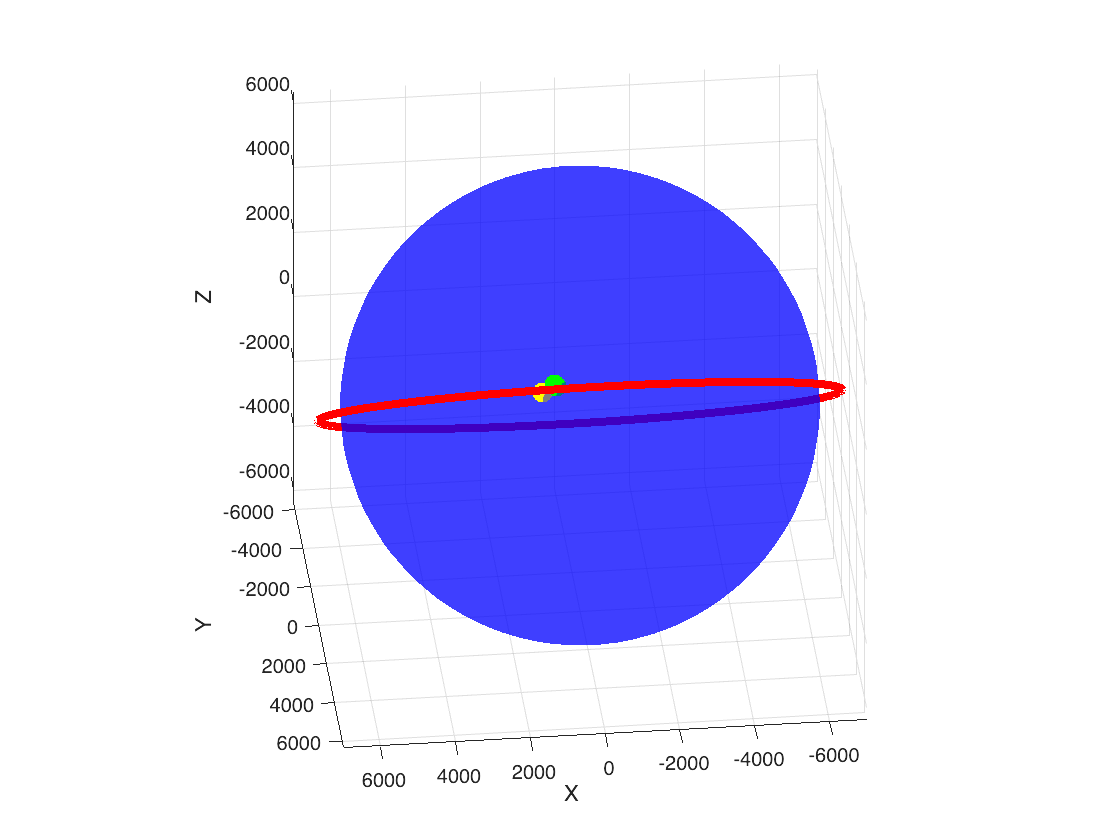

    
    % ------------Communication

        [lat,long]=eci_to_latlong(state(1,1),state(2,1),state(3,1));
        % fprintf('lat: %.1f long%.1f.\n', lat, long);
          distance_to_gs = haversine_distance(lat, long, GS.lat, GS.long);
            if distance_to_gs <= 250 % Assuming 250 km communication range
                 fprintf('Time: %.1f s - CubeSat is over the Ground Station.\n', idx);
                 power_total = power_baseline + power_comm; %Powers Consumption
                  subsystem_mode{idx} = 'Communication';
                  for i = 1:data_rate % Add a rate simluatio nstep
                    if( data_remaining > 0)
        
        
                        % Extract payload for the current packet
                        start_idx = (packet_idx - 1) * packet_size + 1;
                        end_idx = min(packet_idx * packet_size, length(image_vector));
                        payload_data = image_vector(start_idx:end_idx);
        
                        % Build AX.25 Frame
                        lat_long = typecast(single([lat, long]), 'uint8'); % Convert lat/long to bytes
                        header = buildAX25Header(source_address, destination_address, control_field, protocol_id);
                        frame = [preamble, header, lat_long, payload_data'];
        

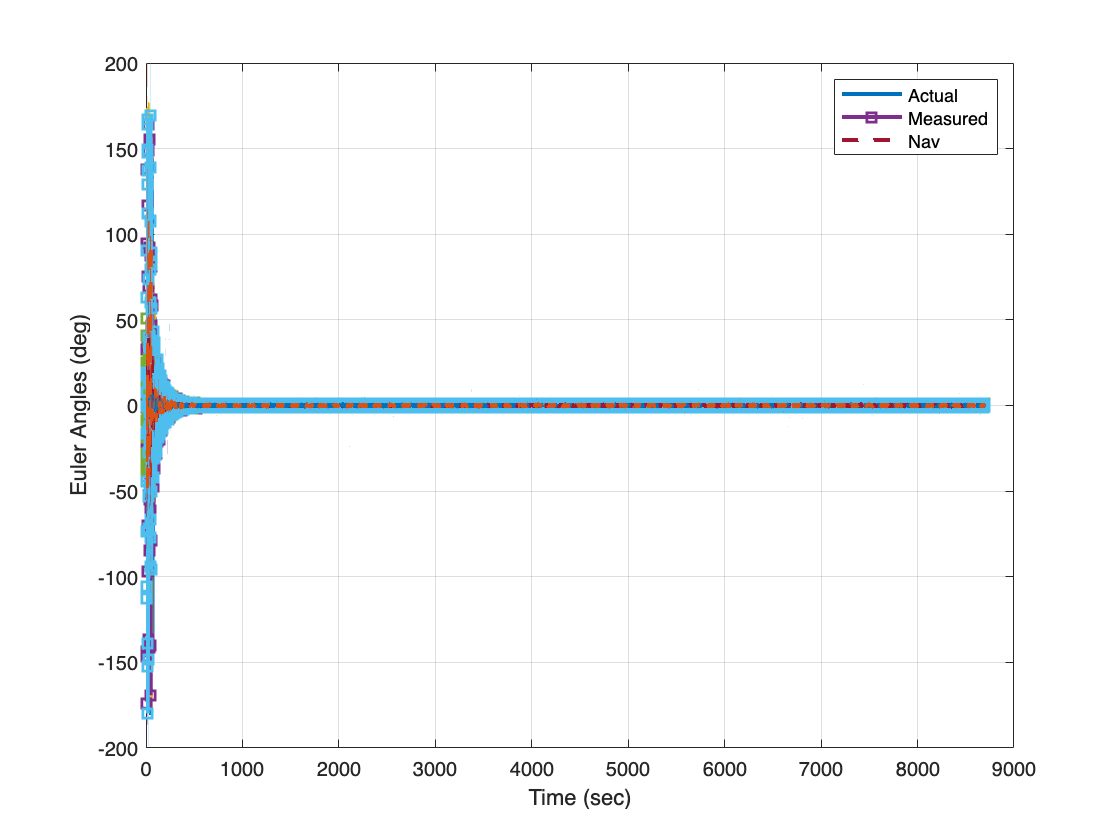

                        % Add Frame Check Sequence (FCS)
                        fcs = calculateCRC(frame);
                        frame = [frame, fcs];
        
                       packet_idx = packet_idx+1;
                       data_remaining = data_remaining -1;
                       if (data_remaining < 1)
                           length(Payload.imageData)
                           Payload.Sent{1}=true;
                           %%%%%Keep unsent data only
                            toKeep = ~[Payload.Sent{:}];
                            Payload.imageData = Payload.imageData(toKeep);
                            Payload.Sent = Payload.Sent(toKeep);
                            length(Payload.imageData);
                       end

                            data_transmitted=data_transmitted+1;

                    % Log Communication Status
                    comm_status.time = [comm_status.time; idx];
                    comm_status.data_transmitted = [comm_status.data_transmitted; data_transmitted];
                    comm_status.data_remaining = [comm_status.data_remaining; data_remaining];
        
                     fprintf('Time: %.1f s - Data Pakect Transmitted: %.2f MB, Data Remaining: %.2f MB\n',idx, data_transmitted,  data_remaining);
        
                    end
        

                   end
        
               end
        
 

This section simulates the CubeSat’s payload operations during passes over the Areas of Interest (AOIs), specifically Baltoro and Siachen glaciers, and prepares captured image data for transmission. Using the Haversine Distance formula, the CubeSat determines its proximity to each AOI. If within the defined 200 km200 \, \text{km} radius, it enters **Imaging Mode**, logs the event, and captures a simulated image represented as a 256x256 matrix. The image, along with a timestamp, is stored in `Payload.imageData` and marked as unsent. Power consumption is updated to include payload operations, and the subsystem mode is set to `'Payload Operation'`. If the CubeSat has at least one unsent image and no data currently in transmission, it prepares the image for downlink by flattening it into a vector, calculating the required number of packets, and initializing the transmission queue with `data_remaining` and `packet_idx`. This logic ensures efficient imaging during AOI passes and seamless data preparation for subsequent transmission.

%----------Payload        
                   
            distance_to_gs = haversine_distance(lat, long, AOIb.center_lat, AOIb.center_long);
            if distance_to_gs <= AOIb.radius_km % Assuming 250 km communication range
                fprintf('Time: %.1f s - CubeSat is over Baltoro.\n', idx);
                    fprintf('Imaging Mode: Capturing image...\n');
                    image = struct('timestamp', datetime, 'data', rand(256, 256)); % Simulated image
                    Payload.imageData{end+1} = image;
                    Payload.Sent{end+1}= false;

                    power_total = power_baseline + power_payload; % Payload Power
                    subsystem_mode{idx} = 'Payload Operation';
            end 
        
        
           distance_to_gs = haversine_distance(lat, long, AOIs.center_lat, AOIs.center_long);
            if distance_to_gs <= AOIs.radius_km % Assuming 250 km communication range
                fprintf('Time: %.1f s - CubeSat is over Siachen.\n', idx);
                    fprintf('Imaging Mode: Capturing image...\n');
                    image = struct('timestamp', datetime, 'data', rand(256, 256)); % Simulated image
                    Payload.imageData{end+1} = image;
                    Payload.Sent{end+1}= false;

                     power_total = power_baseline + power_payload; % Payload Power
                    subsystem_mode{idx} = 'Payload Operation';
            end 
        
        %%%% Convert data in to frames
            if((length(Payload.imageData)>=1) && (data_remaining <= 0))
                image_vector = reshape(Payload.imageData{1}.data, [], 1); % Flatten the image into a 1D array
                num_packets = ceil(length(image_vector) / packet_size); % Number of packets
                data_remaining= num_packets; % remaining data to sent
                packet_idx=1; %Packet to be sent
            end       

end

This section models the CubeSat's energy consumption and battery management during its orbit. The energy consumed at each time step is calculated as the product of total power consumption (`power_total`) and the time step duration (`timestep`). The battery level is dynamically updated based on whether the CubeSat is in sunlight or eclipse. In sunlight, the net power generated by the solar panels (`solar_power`) is used to charge the battery, ensuring it does not exceed its maximum capacity (`battery_storage`). Conversely, in eclipse, the battery discharges to meet the power demands of the subsystems, ensuring it does not fall below zero. If the battery level drops below a predefined safe mode threshold (`safe_mode_threshold`), the satellite enters **Safe Mode**, reducing power consumption to essential systems. This logic ensures efficient power management, maintaining operational continuity while protecting the satellite from power failure.

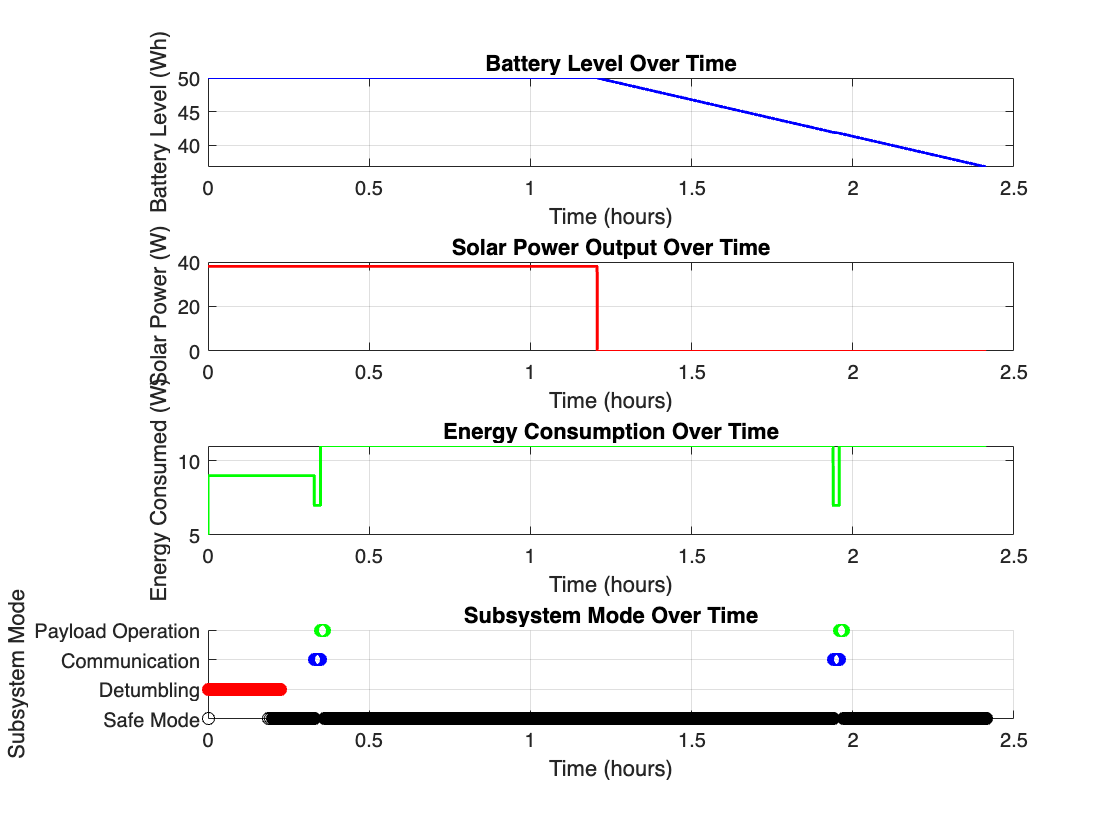

%----------EPS-----------------
  % Energy consumption

    energy_consumed(idx) = power_total * timestep;

    % Update battery level

Elapsed time is 67.078571 seconds.


    if idx > 1
        if in_sunlight(idx)
            % Battery charges in sunlight
            net_power = solar_power(idx) - power_total;
            battery_level(idx) = min(battery_level(idx-1) + net_power * timestep, battery_storage);
        else
            % Battery discharges in eclipse
            battery_level(idx) = max(battery_level(idx-1) - power_total * timestep, 0);
        end
    end

    % Check for safe mode activation
    if battery_level(idx) < safe_mode_threshold
        is_safe_mode = true;
    else
         is_safe_mode = false;
    end







This section implements the **Runge-Kutta 4th Order (RK4)** numerical integration method to propagate the CubeSat’s state over time. RK4 is a widely used and accurate technique for solving ordinary differential equations, making it ideal for simulating the CubeSat’s dynamics. The method involves four function evaluations (`k1`, `k2`, `k3`, and `k4`) at each time step to compute the state update.


    % 
    %%%%Then we make our 4 function calls for the RK4
    k1 = Satellite(tout(idx),state);
    k2 = Satellite(tout(idx)+timestep/2,state+k1*timestep/2);
    k3 = Satellite(tout(idx)+timestep/2,state+k2*timestep/2);
    k4 = Satellite(tout(idx)+timestep,state+k3*timestep);
    k = (1/6)*(k1 + 2*k2 + 2*k3 + k4);
    state = state + k*timestep;
    
    
end

**Description of the Attitude Determination and Control System (ADCS)**

The **Attitude Determination and Control System (ADCS)** is modeled through the `Satellite` function, which simulates the CubeSat's translational and rotational dynamics. The ADCS ensures accurate attitude stabilization and pointing for mission operations, using sensors (magnetometers and gyroscopes) and actuators (magnetorquers and reaction wheels). The function integrates gravitational forces, magnetic field interaction, sensor measurements, and control inputs to compute the derivatives of the satellite's state vector.

**1. Translational Dynamics**

- **State Variables**: 

- `x`, `y`, `z`: Position coordinates in the ECI frame.

- `vel`: Velocity vector ([vx,vy,vz][v_x, v_y, v_z]).

- **Gravitational Forces**: 

- The satellite experiences gravitational acceleration, modeled using: Fgrav=−μmρ2r^\mathbf{F}_{\text{grav}} = -\frac{\mu m}{\rho^2} \hat{r}Where: 

- μ\mu: Gravitational parameter of Earth.

- mm: Satellite mass.

- ρ\rho: Distance from Earth's center.

- r^\hat{r}: Unit vector of position.

- **Disturbance Forces**: 

- Atmospheric drag and magnetic disturbances are computed through the `Disturbance` function.

- **Net Acceleration**: accel=Fgrav+Fdisturbancem\text{accel} = \frac{\mathbf{F}_{\text{grav}} + \mathbf{F}_{\text{disturbance}}}{m}

**2. Rotational Dynamics**

- **State Variables**: 

- `q0123`: Quaternion representation of attitude.

- `pqr`: Angular velocity vector (p,q,rp, q, r).

- **Rotational Kinematics**: 

- The quaternion derivative is computed using: q˙=12PQRMAT⋅q\dot{\mathbf{q}} = \frac{1}{2} \mathbf{PQRMAT} \cdot \mathbf{q}Where PQRMAT\mathbf{PQRMAT} relates angular velocities to quaternion rates.

- **Torque and Angular Momentum**: 

- Total moments, including contributions from: 

- **Magnetorquers**: Interaction of magnetic dipole moments with the local magnetic field.

- **Disturbances**: Environmental torques.

- **Control Input**: Commands to adjust attitude.

- Angular momentum is calculated as: H=Is⋅pqr\mathbf{H} = \mathbf{I_s} \cdot \mathbf{pqr}

- **Rotational Dynamics**: 

- Angular velocity derivative: pqr˙=I−1(LMN−pqr×H)\dot{\mathbf{pqr}} = \mathbf{I}^{-1} \left(\mathbf{LMN} - \mathbf{pqr} \times \mathbf{H}\right)

**3. Sensor Block**

- **Magnetic Field (**`igrfmagm`**)**: 

- Computes Earth's magnetic field at the satellite's position using the IGRF model.

- Converts measurements from NED (North-East-Down) frame to ECI (Earth-Centered Inertial) frame.

- **Sensor Measurements**: 

- Simulated magnetometer and gyroscope data include: 

- **Bias**: Modeled inaccuracies in sensors.

- **Noise**: Stochastic disturbances.

**4. Control Block**

- **Magnetorquer Control**: 

- Generates magnetic dipole moments using: μB=current⋅n⋅A\mu_B = \mathbf{current} \cdot \mathbf{n} \cdot \mathbf{A}

- Computes torques through interaction with the local magnetic field.

- **Saturation**: 

- Limits current to prevent excessive dipole moments or power consumption.

- **Navigation**: 

- Filters raw sensor data to estimate attitude, angular velocity, and magnetic field for control purposes.

**5. Total Dynamics**

The function integrates forces, torques, and disturbances to compute the CubeSat's derivatives:

- Translational dynamics (x˙,v˙\dot{\mathbf{x}}, \dot{\mathbf{v}}).

- Rotational dynamics (q˙,pqr˙\dot{\mathbf{q}}, \dot{\mathbf{pqr}}). These are returned as `dstatedt`, representing the state changes over time.

**Highlights of ADCS Functionality**

- **Dynamic Magnetic Field Modeling**: 

- Real-time magnetic field calculations using IGRF.

- **Integrated Control**: 

- Magnetorquers adjust attitude using feedback from sensors.

- **Environmental Disturbance Handling**: 

- Models aerodynamic drag, magnetic torques, and gravity gradients.

- **Robust Navigation**: 

- Combines sensor inputs to refine state estimates.

%%%Save original State
stateout_original = stateout;
disp('Simulation Complete')
toc

%%Convert state to kilometers
stateout(:,1:6) = stateout_original(:,1:6)/1000;

%%%Extract the state vector
xout = stateout(:,1);
yout = stateout(:,2);
zout = stateout(:,3);
q0123out = stateout(:,7:10);
ptpout = Quaternions2EulerAngles(q0123out);
pqrout = stateout(:,11:13);
%w123 = stateout(:,14:16);


%%%Make an Earth
[x_sphere, y_sphere, z_sphere] = sphere(50);

%%%Plot 3D orbit
fig = figure();
set(fig,'color','white')

plot3(xout,yout,zout,'r','LineWidth',4)
hold on
xlabel('X')
ylabel('Y')
zlabel('Z')
grid on
hold on
% Plot Earth as a Sphere
surf(1e-3*R * x_sphere, 1e-3*R * y_sphere, 1e-3*R * z_sphere, ...
    'FaceColor', 'blue', 'EdgeColor', 'none', 'FaceAlpha', 0.5);
hold on;
axis equal


% Plot AOI as a Point
[aoi_x, aoi_y, aoi_z] = latlong_to_cartesian(AOIs.center_lat, AOIs.center_long, 1e-3*R);
scatter3(aoi_x, aoi_y, aoi_z, 100, 'g', 'filled', 'DisplayName', 'Area of Interest');
hold on;

[aoi_x, aoi_y, aoi_z] = latlong_to_cartesian(AOIb.center_lat, AOIb.center_long, 1e-3*R);
scatter3(aoi_x, aoi_y, aoi_z, 100, 'g', 'filled', 'DisplayName', 'Area of Interest');
hold on;

% Plot Ground Station
[gs_x, gs_y, gs_z] = latlong_to_cartesian(GS.lat, GS.long, 1e-3*R);
scatter3(gs_x, gs_y, gs_z, 100, 'y', 'filled', 'DisplayName', 'Ground Station');

%view([-227 24]);
 hold off;

view([-186 31])



%%%plot Euler Angles
fig4 = figure();
set(fig4,'color','white')
p1 = plot(tout,ptpout*180/pi,'-','LineWidth',2);
hold on
p2 = plot(tout,ptpm*180/pi,'-s','LineWidth',2);
p3 = plot(tout,ptpN*180/pi,'--','LineWidth',2);
grid on
xlabel('Time (sec)')
ylabel('Euler Angles (deg)')
legend('Phi','Theta','Psi')
legend([p1(1),p2(1),p3(1)],'Actual','Measured','Nav')





% Convert battery level to Watt-hours for easier interpretation
battery_level_wh = battery_level / 3600;

% Visualization
figure;

% Plot Battery Level
subplot(4, 1, 1);
plot(tout / 3600, battery_level_wh, 'b', 'LineWidth', 1.5);
xlabel('Time (hours)');
ylabel('Battery Level (Wh)');
title('Battery Level Over Time');
grid on;

% Plot Solar Power
subplot(4, 1, 2);
plot(tout / 3600, solar_power, 'r', 'LineWidth', 1.5);
xlabel('Time (hours)');
ylabel('Solar Power (W)');
title('Solar Power Output Over Time');
grid on;

% Plot Energy Consumption
subplot(4, 1, 3);
plot(tout / 3600, energy_consumed / timestep, 'g', 'LineWidth', 1.5);
xlabel('Time (hours)');
ylabel('Energy Consumed (W)');
title('Energy Consumption Over Time');
grid on;

% Plot Subsystem Mode
subplot(4, 1, 4);
hold on;
for idx = 1:length(tout)
    if strcmp(subsystem_mode{idx}, 'Detumbling')
        plot(tout(idx) / 3600, 1, 'ro');
    elseif strcmp(subsystem_mode{idx}, 'Communication')
        plot(tout(idx) / 3600, 2, 'bo');
    elseif strcmp(subsystem_mode{idx}, 'Payload Operation')
        plot(tout(idx) / 3600, 3, 'go');
    else
        plot(tout(idx) / 3600, 0, 'ko');
    end
end
xlabel('Time (hours)');
ylabel('Subsystem Mode');
title('Subsystem Mode Over Time');
yticks([0, 1, 2, 3]);
yticklabels({'Safe Mode', 'Detumbling', 'Communication', 'Payload Operation'});
grid on;


toc



function [x, y, z] = latlong_to_cartesian(lat, long, radius)
    % Convert latitude and longitude to Cartesian coordinates
    x = radius * cosd(lat) * cosd(long);
    y = radius * cosd(lat) * sind(long);
    z = radius * sind(lat);
end
function distance = haversine_distance(lat1, long1, lat2, long2)
    % Calculate the great-circle distance between two points on a sphere
    R = 6371; % Earth's radius in km
    dlat = deg2rad(lat2 - lat1);
    dlong = deg2rad(long2 - long1);
    a = sin(dlat/2)^2 + cos(deg2rad(lat1)) * cos(deg2rad(lat2)) * sin(dlong/2)^2;
    c = 2 * atan2(sqrt(a), sqrt(1-a));
    distance = R * c;
end
function [lat, long] = eci_to_latlong(x, y, z)
    % Convert ECI coordinates to latitude and longitude
   
    rho = norm([x;y;z]);

    thetaE = acos(z/rho);
    psiE = atan2(y,x);

    
    lat = 90 - rad2deg(thetaE); %90-thetaE*180/p;
    long = rad2deg(psiE);%*180/pi;




    % lat = asind(z / rho);
    % long = atan2d(y, x);
   
end
function header = buildAX25Header(src, dest, control, pid)
    % AX.25 Header Construction
    header = [encodeCallsign(dest), encodeCallsign(src), control, pid];
end

function encoded = encodeCallsign(callsign)
    % Encode a 6-character callsign into AX.25 format
    callsign = pad(callsign, 6, 'right', ' '); % Ensure callsign is 6 characters
    encoded = uint8(callsign) * 2; % Shift ASCII values left by 1 bit
end

function crc = calculateCRC(data)
    % CRC-16-CCITT Calculation (FCS)
    polynomial = uint16(0x1021);
    crc = uint16(0xFFFF);
    for byte = data
        crc = bitxor(crc, bitshift(uint16(byte), 8));
        for bit = 1:8
            if bitand(crc, uint16(0x8000))
                crc = bitxor(bitshift(crc, 1), polynomial);
            else
                crc = bitshift(crc, 1);
            end
        end
    end
    crc = uint8([bitshift(crc, -8), bitand(crc, uint16(0xFF))]); % Convert to 2 bytes
end